**Artificial Intelligence/Machine Learning - Coursework**

**Robert Parry - 19028639**

**1)** Filesize - based features ~ Working

**2)** Brightness - based features ~ Working

**3)** Edge - based features ~ Not fully working

**4)** HOG1 - based features ~ Working

**5)** BoVW2 - based features ~ Not fully working - worked once then stopped

**6)** CNN - based features

   ** i)** resnet50 ~ Working

   ** ii)** alexnet ~ Working

**7)** Extra - KNN ~ Working

**8)** Functions

**1. Filesize-based features**

%Reading the file sizes of each picture, then inputting them into a table
    % load the dataset:
    data = readcell('MerchData.csv');
    
    % Create the dataset array
    data(1:1:10, 1:1:end)

ans = 10×2 cell array
    {'filesize'}    {'object'}
    {[    6070]}    {'Hat'   }
    {[    4472]}    {'Hat'   }
    {[    3997]}    {'Hat'   }
    {[    5023]}    {'Hat'   }
    {[    5427]}    {'Hat'   }
    {[    5410]}    {'Hat'   }
    {[    5003]}    {'Hat'   }
    {[    4696]}    {'Hat'   }
    {[    4220]}    {'Hat'   }


    data(1, :) = [];
    
    % Populate the array with the data
    data = data(randperm(size(data,1)), :);
    

    rng(0); % please leave this re-seeding of the random number generator in place so we can compare results
    
    % Set the variable values using 'data'
    nTest = round(0.4 * size(data,1))

nTest = 30

    data_test = data(1:1:nTest, :);
    data_train = data(nTest+1:1:end, :);
    
   
    %Set the label index based on how many label columns needed
    label_index = 2;
    %Set test_labels/examples data using the previous data test and train vars
    test_labels = categorical(data_test(:, label_index));
    test_examples = cell2mat(data_test(:, 1:end~=label_index));
    %Set train_labels/examples data using the previous data test and train vars
    train_labels = categorical(data_train(:, label_index));
    train_examples = cell2mat(data_train(:, 1:end~=label_index));
    
        
    %Set var 'm_knn'  to use the function for 'knn' using the two stated variables
    m_knn = fitcknn(train_examples, train_labels)

m_knn =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Cards    Cube    Hat    Screwdriver    Torch]
           ScoreTransform: 'none'
          NumObservations: 45
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


    
    %Set var 'm_nb'  to use the function for 'cnb' using the two stated variables
    m_nb = fitcnb(train_examples, train_labels)

m_nb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [Cards    Cube    Hat    Screwdriver    Torch]
            ScoreTransform: 'none'
           NumObservations: 45
         DistributionNames: {'normal'}
    DistributionParameters: {5×1 cell}


  Properties, Methods


    
    %Set var 'm_dt'  to use the function for 'tree' using the two stated variables
    m_dt = fitctree(train_examples, train_labels)

m_dt =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Cards    Cube    Hat    Screwdriver    Torch]
           ScoreTransform: 'none'
          NumObservations: 45


  Properties, Methods


    
    %Set var 'm_ann'  to use the function for 'net' using the two stated variables
    m_ann = fitcnet(train_examples, train_labels)

m_ann =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Cards    Cube    Hat    Screwdriver    Torch]
           ScoreTransform: 'none'
          NumObservations: 45
               LayerSizes: 10
              Activations: 'relu'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [2×7 table]


  Properties, Methods


    
    %Set var 'm_svm'  to use the function for 'ecoc' using the two stated variables
    m_svm = fitcecoc(train_examples, train_labels)

m_svm =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Cards    Cube    Hat    Screwdriver    Torch]
           ScoreTransform: 'none'
           BinaryLearners: {10×1 cell}
               CodingName: 'onevsone'


  Properties, Methods


    
    
%Prediction Setup 
    %Using the trained classifier to predict using the 'test_examples'
    predictions = predict(m_knn, test_examples);
    
    %Using the trained classifier to predict using the 'test_examples'
    %Set var 'predictions1'  to use the function for predict using the two stated variables
    predictions1 = predict(m_nb, test_examples);
    
    %Using the trained classifier to predict using the 'test_examples'
    %Set var 'predictions2'  to use the function for predict using the two stated variables
    predictions2 = predict(m_dt, test_examples);
    
    %Using the trained classifier to predict using the 'test_examples'
    %Set var 'predictions3'  to use the function for predict using the two stated variables
    predictions3 = predict(m_ann, test_examples);
    
    %Using the trained classifier to predict using the 'test_examples'
    %Set var 'predictions4'  to use the function for predict using the two stated variables
    predictions4 = predict(m_svm, test_examples);
    
    
%KNN Evaluation
    
    %Create a confusion matrix using 'test_labels' and 'predictions'
    [c, order] = confusionmat(test_labels, predictions)

c =      2     0     4     3     0
     0     4     0     0     1
     0     0     3     1     0
     1     0     0     5     0
     0     0     3     1     2


order = 5×1 categorical array
     Cards 
     Cube 
     Hat 
     Screwdriver 
     Torch 


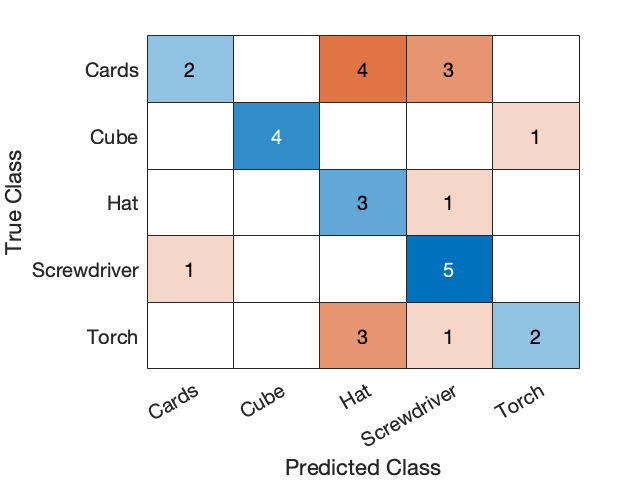

    
    %Create and display a confusion chart using 'test labels' and predictions
    confusionchart(test_labels, predictions)

    
    %Output accuracy
    p = sum(diag(c)) / sum(c(1:1:end))

p = 0.5333


%NB Evaluation
       
    [c, order] = confusionmat(test_labels, predictions1)

c =      1     0     6     2     0
     0     5     0     0     0
     0     0     3     1     0
     1     0     0     5     0
     1     1     4     0     0


order = 5×1 categorical array
     Cards 
     Cube 
     Hat 
     Screwdriver 
     Torch 


    
    
    confusionchart(test_labels, predictions1)

    
    
    p = sum(diag(c)) / sum(c(1:1:end))

p = 0.4667


%DT Evaluation
       
    [c, order] = confusionmat(test_labels, predictions2)

c =      3     0     3     2     1
     0     4     0     0     1
     1     0     3     0     0
     3     0     0     3     0
     1     0     1     0     4


order = 5×1 categorical array
     Cards 
     Cube 
     Hat 
     Screwdriver 
     Torch 


    
   
    confusionchart(test_labels, predictions2)

    
    
    p = sum(diag(c)) / sum(c(1:1:end))

p = 0.5667


%ANN Evaluation
     
    [c, order] = confusionmat(test_labels, predictions3)

c =      0     0     9     0     0
     0     0     5     0     0
     0     0     4     0     0
     0     0     6     0     0
     0     0     6     0     0


order = 5×1 categorical array
     Cards 
     Cube 
     Hat 
     Screwdriver 
     Torch 


       
    confusionchart(test_labels, predictions3)

    
    p = sum(diag(c)) / sum(c(1:1:end))

p = 0.1333


%SVM Evaluation
    [c, order] = confusionmat(test_labels, predictions4)

c =      3     0     2     2     2
     0     4     0     0     1
     1     0     1     0     2
     2     0     0     4     0
     1     0     2     0     3


order = 5×1 categorical array
     Cards 
     Cube 
     Hat 
     Screwdriver 
     Torch 


    
    confusionchart(test_labels, predictions4)

    
    p = sum(diag(c)) / sum(c(1:1:end))

p = 0.5000

**2. Brightness-based features     **

%Data    
    %Check the dataset is present:
    if ~exist('./MerchData', 'dir')
        error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
    end


%Working with the datastore  
    %Create the imagedatastore object:
    imds = imageDatastore('MerchData', 'IncludeSubfolders', true);
    
    % loop over all the images extracting their size
    grow = [];
    imds.reset();
    while hasdata(imds)
        im = imds.read();
        grow(end+1,:) = size(im); % store the dimensions of the image (height, width, depth)
    end
    
    size(grow)

ans =     75     3




%Splitting image dataset
    rng(0);
    
    %Using 'MerchData' to populate 'imds'
    imds = imageDatastore('MerchData', 'IncludeSubfolders', true, 'LabelSource','foldernames')

imds =   ImageDatastore with properties:

                       Files: {
                              '/Users/robertparry/Documents/MATLAB/MerchData/MathWorks Cap/Hat_0.jpg';
                              ' .../robertparry/Documents/MATLAB/MerchData/MathWorks Cap/Hat_123.jpg';
                              ' .../robertparry/Documents/MATLAB/MerchData/MathWorks Cap/Hat_148.jpg'
                               ... and 72 more
                              }
                     Folders: {
                              '/Users/robertparry/Documents/MATLAB/MerchData'
                              }
                      Labels: [MathWorks Cap; MathWorks Cap; MathWorks Cap ... and 72 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     Read

    [training, testing] = splitEachLabel(imds, 0.6, 'randomize');

    %Set 'im' to the first image from training
    im = training.readimage(1)

im = 227×227×3 uint8 array
im(:,:,1) =

   163   163   163   164   164   165   165   165   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161   161   161   162   161   161   160   160   161   161   162   161   161   161   160   160   159   159   159   160   160   160   161   163   164   165   165   168   168   170   170   171   171   171   171   170   170   168   168   167   167   165   165   162   161   161   160   159   159   160   161   163   165   166   166   166   166   167   167   168   168   168   168   168   168   168   166   170   168   168   169   170   172   175   177   172   171   170   169   169   169   169   169   172   171   171   170   168   167   165   165   168   168   168   168   168   168   168   168   172   172   172   173   173   174   174   174   174   174   174   174   174   174   174   175   178   179   178   178   178   179   179   179   181   178   178   175   175   171   169   169

    %im = my_im2gray(im)
    imshow(im);
    
    %Use the size function with 'im' as the input
    size(im)

ans =    227   227     3



    %Convert the loaded image from rgb(colour) to greyscale(black&white)
    im = im2gray(im);
    size(im)

ans =    227   227


    x = size(im)

x =    227   227


    n = x(1,2) * x(1,2)

n = 51529

    %Output the loaded image
    imshow(im);

%Testing code
    %Read the image and put it in an array
    my2dimagearray = imread('cameraman.tif');
    imshow(my2dimagearray);

    %Changing the brightness value of the 100th value
    my2dimagearray(100,50) = 255;
    imshow(my2dimagearray)

% %Working with the image data - testing
%     
%     %Load the first image from the dataset into the var 'im'
%     im = training.readimage(1)
%     imshow(im);
%     
%     %calculate average brightness of an image
%     brightness = mean2(im)
%     
%     %Create and populate the array 'imageArray' with the data from 'im'
%     imageArray = []
%     imageArray = im
%     
%     %Create and populate the var 'summedImage' with the summed values from 'ImageArray'
%     summedImage = sum(imageArray(),"all")
%     
%     finbri = summedImage / n



%Setting up and running the training data
    %Populate the training data using the images in the dataset and extracting
    %the relavent data using the 'get_brightness()' function
    train_examples = [];
    while hasdata(training)
    %Convert the training image to greyscale
    im = im2gray(training.read());
    %Populate 'train_examples' using the 'get_brightness' function
    train_examples(end+1,:) = get_brightness(im);
    end

ans =    227   227


x =    227   227


n = 51529

brightness = 125.3076


imageArray =

     []



imageArray = 227×227 uint8 matrix
   177   177   177   178   178   179   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   173   173   172   172   172   173   173
   177   177   177   178   178   178   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   173   173   173   172   172   173   173
   177   177   177   177   178   178   178   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   174   173   173   173   172   173   174
   176   176   177   177   177   178   178   178   178   178   

summedImage = 6456973

finbri = 125.3076

b = 125.3076

ans =    227   227


x =    227   227


n = 51529

brightness = 131.4523


imageArray =

     []



imageArray = 227×227 uint8 matrix
   124   123   122   120   119   117   116   115   114   113   111   110   109   109   110   111   107   108   108   109   109   110   110   111   105   105   105   105   105   105   105   105   106   105   104   104   104   106   108   109   110   110   111   112   113   113   114   114   113   113
   114   113   113   113   113   113   112   112   109   109   108   107   107   108   110   110   110   110   110   110   110   111   111   111   110   110   110   110   110   110   110   110   111   111   110   110   110   111   112   112   112   112   112   113   114   115   115   116   114   114
   103   104   105   106   107   108   109   110   108   107   107   107   108   109   111   111   112   111   111   111   111   111   110   110   114   114   114   114   114   114   114   114   113   113   113   113   113   113   112   111   111   112   112   113   114   115   115   116   114   114
   103   103   104   105   107   108   109   110   111   111   

summedImage = 6773608

finbri = 131.4523

b = 131.4523

ans =    227   227


x =    227   227


n = 51529

brightness = 111.0960


imageArray =

     []



imageArray = 227×227 uint8 matrix
   207   207   207   207   206   206   206   206   206   206   206   205   205   205   205   205   209   208   207   206   206   206   207   208   210   207   204   202   203   204   205   204   206   208   210   209   203   190   174   163   151   151   150   150   149   148   147   147   143   143
   205   205   205   205   205   205   205   205   207   207   207   206   206   206   206   206   202   203   206   208   209   208   207   206   210   209   209   211   212   213   211   209   216   207   192   177   164   153   144   139   150   150   150   149   148   147   147   146   146   146
   207   207   208   208   208   208   208   208   209   209   209   210   210   210   210   210   204   205   206   207   207   207   207   207   207   207   208   210   210   206   200   196   180   170   156   146   143   146   152   155   149   149   148   147   147   146   145   145   145   145
   213   213   213   213   214   214   214   214   213   213   

summedImage = 5724668

finbri = 111.0960

b = 111.0960

ans =    227   227


x =    227   227


n = 51529

brightness = 120.8475


imageArray =

     []



imageArray = 227×227 uint8 matrix
   130   135   136   132   129   130   130   128   126   127   127   128   128   127   127   126   128   127   125   124   124   125   127   128   124   125   125   126   126   125   125   124   128   127   126   125   126   127   129   130   129   129   128   128   128   129   130   131   134   136
   129   134   135   131   129   130   130   127   126   127   127   128   128   127   127   126   127   126   125   125   125   125   126   127   124   125   125   126   126   125   125   124   127   127   126   125   126   127   128   129   127   126   126   126   126   127   128   129   134   136
   128   132   134   130   128   129   129   126   126   126   127   127   127   127   126   126   126   126   125   125   125   125   126   126   124   125   125   126   126   125   125   124   126   126   126   125   126   127   128   129   126   126   126   126   126   127   128   129   133   134
   126   130   132   128   126   128   128   125   125   126   

summedImage = 6227149

finbri = 120.8475

b = 120.8475

ans =    227   227


x =    227   227


n = 51529

brightness = 133.2403


imageArray =

     []



imageArray = 227×227 uint8 matrix
    96   111   124   126   127   129   129   126   127   128   131   135   138   139   136   134   121   102   109   122   115   118   127   120   121   119   119   120   116   111   111   115   112   115   115   112   112   114   114   111   106   108   111   114   115   115   115   114   108   112
   104   115   123   123   121   124   125   124   124   125   128   132   135   136   133   130   121    98   100   115   114   116   123   119   120   118   118   119   117   112   112   116   111   114   114   111   111   114   114   111   107   107   107   108   110   111   113   114   108   112
   114   120   123   119   117   118   120   121   120   121   124   128   131   131   129   126   120    92    86   104   111   113   117   116   114   113   113   115   113   110   110   115   110   113   113   110   110   113   113   110   109   108   107   106   107   110   112   114   110   113
   120   122   122   120   117   116   117   118   118   119   

summedImage = 6865741

finbri = 133.2403

b = 133.2403

ans =    227   227


x =    227   227


n = 51529

brightness = 140.1748


imageArray =

     []



imageArray = 227×227 uint8 matrix
   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   197   196   194   193   192   193   194   195   193   193   193   193   193   193   193   193   193   193   193   194   194   195   195   195   193   193
   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   196   195   194   192   192   192   193   194   193   193   193   193   193   193   193   193   193   193   193   194   194   195   195   195   194   194
   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   194   193   192   192   192   192   193   193   193   193   193   193   193   193   193   193   193   193   194   194   195   195   195   195   195
   195   195   195   195   195   195   195   195   195   195   

summedImage = 7223065

finbri = 140.1748

b = 140.1748

ans =    227   227


x =    227   227


n = 51529

brightness = 131.9729


imageArray =

     []



imageArray = 227×227 uint8 matrix
   183   182   181   181   180   179   178   178   178   177   176   174   174   174   174   174   170   170   171   171   172   172   173   173   171   170   170   170   172   175   179   181   183   183   182   180   180   180   180   180   180   180   181   182   183   183   183   182   184   185
   182   181   181   180   179   178   178   177   176   175   174   173   173   173   173   173   173   173   173   173   174   174   175   175   175   174   174   174   175   178   181   183   183   182   181   180   180   180   181   181   181   182   183   183   184   184   184   183   184   185
   181   181   180   179   179   178   178   177   175   175   174   173   173   173   174   174   177   177   177   177   178   178   178   178   180   180   179   179   180   182   184   185   182   181   181   181   181   182   182   183   183   184   185   185   186   186   185   185   185   185
   181   181   180   180   179   179   179   178   177   177   

summedImage = 6800433

finbri = 131.9729

b = 131.9729

ans =    227   227


x =    227   227


n = 51529

brightness = 122.3613


imageArray =

     []



imageArray = 227×227 uint8 matrix
   181   181   181   181   181   181   181   181   182   182   182   182   182   182   182   182   183   183   183   183   183   183   183   183   182   182   180   179   179   179   179   179   178   179   179   180   181   182   183   183   186   186   185   184   183   183   182   182   181   181
   182   182   182   182   182   182   182   182   182   182   182   182   182   182   182   182   183   183   183   183   183   183   183   183   182   181   180   180   179   179   179   180   179   180   180   181   182   183   184   184   186   186   186   185   184   183   183   182   181   181
   182   182   182   182   182   182   182   182   182   182   182   182   182   182   182   182   183   183   183   183   183   183   183   183   182   181   181   180   179   180   180   180   181   182   182   183   184   184   185   185   187   187   186   185   185   184   183   183   181   181
   183   183   183   183   183   183   183   183   182   182   

summedImage = 6305153

finbri = 122.3613

b = 122.3613

ans =    227   227


x =    227   227


n = 51529

brightness = 128.4610


imageArray =

     []



imageArray = 227×227 uint8 matrix
   191   191   191   191   191   191   191   191   187   190   199   197   188   192   196   186   191   202   189   185   196   175   152   166   151   146   142   143   149   153   151   149   139   140   141   139   136   134   134   134   131   133   133   130   125   121   121   122   125   124
   191   191   191   191   191   191   191   191   195   190   192   192   187   193   198   192   173   199   196   175   169   160   149   152   154   151   148   147   147   146   143   141   134   135   137   137   135   134   135   136   131   131   130   126   123   122   124   127   123   123
   191   191   191   191   191   191   191   191   198   187   188   193   189   191   195   190   189   192   185   168   155   148   147   149   158   156   153   149   145   140   135   132   132   134   135   134   132   132   133   134   131   129   126   123   121   122   126   129   120   120
   191   191   191   191   191   191   191   191   194   184   

summedImage = 6619465

finbri = 128.4610

b = 128.4610

ans =    227   227


x =    227   227


n = 51529

brightness = 123.4176


imageArray =

     []



imageArray = 227×227 uint8 matrix
   131   131   130   129   129   128   127   127   128   127   127   127   127   128   129   130   129   130   132   133   134   135   135   135   138   138   138   137   137   136   136   136   136   136   135   134   133   132   132   131   132   132   132   133   133   133   134   134   133   134
   131   131   130   129   128   128   127   127   128   127   127   127   127   128   129   130   129   130   132   133   134   135   135   135   138   138   138   137   137   136   136   136   137   137   136   135   134   133   133   132   133   133   133   134   134   134   135   135   134   135
   131   130   130   129   128   127   127   127   127   127   127   127   127   128   129   129   129   130   132   133   134   135   135   135   138   138   138   137   137   136   136   136   138   137   137   136   136   135   134   134   134   134   135   135   135   136   136   136   136   136
   130   130   129   129   128   127   126   126   127   127   

summedImage = 6359588

finbri = 123.4176

b = 123.4176

ans =    227   227


x =    227   227


n = 51529

brightness = 137.5285


imageArray =

     []



imageArray = 227×227 uint8 matrix
   142   143   143   144   144   143   143   142   143   143   143   144   144   145   145   145   145   146   146   147   147   146   146   145   147   147   147   148   148   149   149   149   149   149   149   149   149   149   149   149   148   148   148   149   149   150   150   150   150   150
   142   143   143   144   144   143   143   142   143   143   143   144   144   145   145   145   145   146   146   147   147   146   146   145   147   147   147   148   148   149   149   149   149   149   149   149   149   149   149   149   148   148   148   149   149   150   150   150   150   150
   142   143   143   144   144   143   143   142   143   143   143   144   144   145   145   145   145   146   146   147   147   146   146   145   147   147   147   148   148   149   149   149   149   149   149   149   149   149   149   149   148   148   148   149   149   150   150   150   150   150
   142   143   143   144   144   143   143   142   143   143   

summedImage = 7086707

finbri = 137.5285

b = 137.5285

ans =    227   227


x =    227   227


n = 51529

brightness = 129.6541


imageArray =

     []



imageArray = 227×227 uint8 matrix
   133   134   135   137   140   142   143   144   142   143   144   146   148   151   152   153   158   159   160   161   162   164   165   165   164   164   164   165   165   165   166   166   167   167   169   170   171   172   172   172   172   173   174   175   174   173   172   171   173   173
   135   136   138   140   142   144   145   146   146   147   148   150   152   154   156   157   160   160   161   162   164   165   166   166   166   166   166   166   167   167   167   168   167   168   169   171   172   172   172   172   172   173   174   175   175   174   173   172   173   174
   139   140   141   143   145   147   148   149   151   152   154   155   157   159   161   161   162   163   163   165   166   167   168   168   167   168   168   168   169   169   169   169   169   169   171   172   172   173   172   172   173   173   174   175   175   174   174   173   175   175
   144   144   146   147   149   151   152   153   156   157   

summedImage = 6680946

finbri = 129.6541

b = 129.6541

ans =    227   227


x =    227   227


n = 51529

brightness = 138.8129


imageArray =

     []



imageArray = 227×227 uint8 matrix
   158   162   165   166   163   162   163   165   163   167   169   165   159   164   182   199   201   205   216   219   214   220   222   211   214   217   219   217   214   213   215   218   215   215   216   214   215   214   214   214   216   210   206   212   221   219   203   188   172   161
   157   158   160   160   162   167   175   181   194   196   195   186   171   168   188   213   225   209   208   214   212   214   219   218   221   216   210   209   212   215   215   215   215   215   215   215   215   215   214   214   219   217   216   219   221   221   214   208   191   176
   170   173   178   183   189   196   205   211   214   212   210   198   174   160   179   208   205   190   200   224   226   218   216   216   217   214   211   211   212   214   214   214   215   215   216   215   215   215   215   214   215   217   218   217   215   215   217   220   209   193
   194   198   203   208   209   207   205   203   198   194   

summedImage = 7152889

finbri = 138.8129

b = 138.8129

ans =    227   227


x =    227   227


n = 51529

brightness = 127.6401


imageArray =

     []



imageArray = 227×227 uint8 matrix
   204   202   178   136   101    90    88    86   106   147   190   210   217   224   228   226   232   228   231   239   243   240   238   240   233   225   217   215   217   217   216   213   217   217   218   217   215   214   215   217   216   194   162   137   129   143   167   185   216   217
   194   206   216   221   219   202   162   125    79    76    88   123   169   206   226   233   225   236   235   226   232   245   239   217   216   220   224   222   219   217   217   220   216   219   221   218   206   189   174   165   134   129   133   150   178   203   214   216   215   216
   209   215   218   217   222   229   226   218   175   136    93    75    78   101   141   178   214   240   249   231   222   235   242   236   234   229   220   213   209   210   213   216   224   216   198   174   153   138   131   131   155   170   192   209   218   220   219   219   215   215
   216   225   229   226   225   232   240   244   241   229   

summedImage = 6577169

finbri = 127.6401

b = 127.6401

ans =    227   227


x =    227   227


n = 51529

brightness = 130.2634


imageArray =

     []



imageArray = 227×227 uint8 matrix
   133   133   133   134   134   135   135   135   135   135   135   136   136   137   137   137   137   137   137   138   138   139   139   139   138   138   138   138   138   138   138   138   140   140   140   141   141   142   142   142   142   142   142   142   142   142   142   142   142   142
   133   133   133   134   134   134   135   135   135   135   135   136   136   137   137   137   137   137   137   138   138   139   139   139   138   138   138   138   138   138   138   138   140   140   140   141   141   142   142   142   142   142   142   142   142   142   142   142   142   142
   133   133   133   133   134   134   134   135   135   135   135   136   136   137   137   137   137   137   137   138   138   139   139   139   138   138   138   138   138   138   138   138   140   140   140   141   141   142   142   142   142   142   142   142   142   142   142   142   142   142
   132   132   133   133   133   134   134   134   135   135   

summedImage = 6712342

finbri = 130.2634

b = 130.2634

ans =    227   227


x = 1×2
   227   227


n = 51529

brightness = 136.7479


imageArray =

     []



imageArray = 227×227
   181   181   181   181   181   181   181   181   181   181   180   180   180   179   179   179   179   179   179   179   179   179   179   179   176   176   177   178   178   177
   181   181   181   181   181   181   181   181   181   181   181   181   180   180   179   179   179   179   179   179   179   179   179   179   178   178   179   180   180   179
   183   183   183   183   183   183   183   183   182   182   182   181   181   181   180   180   180   180   180   180   180   180   180   180   180   181   181   182   182   181
   184   184   184   184   184   184   184   184   183   183   183   183   182   182   181   181   181   181   181   181   181   181   181   181   181   182   182   183   183   182
   186   186   186   186   186   186   186   186   185   185   184   184   183   183   183   183   183   183   183   183   183   183   183   183   181   182   182   183   183   182
   187   187   187   187   187   187   187   187   186   186   185   185  

summedImage = 7046485

finbri = 136.7479

b = 136.7479

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 127.7639


imageArray =

     []



imageArray = 227×227
    65    65    65    66    66    66    67    67    64    65    66    67    68    68    68    68    71    71    72    72    73    74    74    75    75    76    77    78    79    79
    66    66    66    67    67    67    68    68    66    67    68    70    70    71    71    70    72    72    73    74    74    75    76    76    76    77    78    79    80    80
    67    68    68    68    69    69    69    70    70    70    72    73    74    74    74    74    74    75    75    76    77    77    78    78    79    79    81    82    83    83
    70    70    70    71    71    71    72    72    72    73    74    75    76    77    76    76    77    78    78    79    80    81    81    81    81    82    84    85    87    87
    72    72    73    73    73    74    74    74    74    75    76    77    78    78    78    78    81    81    81    82    83    84    84    85    85    86    87    89    90    91
    74    75    75    75    76    76    76    77    77    77    79    80  

summedImage = 6583544

finbri = 127.7639

b = 127.7639

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 117.4718


imageArray =

     []



imageArray = 227×227
   129   129   129   128   128   127   127   127   127   126   126   125   125   126   126   127   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   129   129   128   128   128   127   127   127   127   126   126   125   125   126   126   127   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   129   128   128   128   127   127   127   127   126   126   125   125   125   125   126   126   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   128   128   128   127   127   127   126   126   126   126   125   124   124   125   126   126   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   128   128   127   127   127   126   126   126   126   125   124   124   124   124   125   126   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   127   127   127   127   126   126   126   125   125   125   124   124  

summedImage = 6053204

finbri = 117.4718

b = 117.4718

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 97.7427


imageArray =

     []



imageArray = 227×227
   72   72   72   71   71   70   70   70   71   71   71   71   71   71   71   71   72   72   72   73   73   74   74   74   75   75   75   75   75   75
   72   72   72   71   71   70   70   70   71   71   71   71   71   71   71   71   72   72   73   73   73   74   74   74   75   75   75   75   75   75
   72   72   72   72   71   71   71   71   71   71   71   71   71   71   71   71   72   73   73   73   74   74   74   74   75   75   75   75   75   75
   72   72   72   72   72   72   72   71   72   72   72   72   72   72   72   72   73   73   73   74   74   74   75   75   76   76   76   76   76   76
   72   72   72   72   72   72   72   73   72   72   72   72   72   72   72   72   73   73   74   74   74   75   75   75   76   76   76   76   76   76
   72   72   72   72   73   73   73   73   73   73   73   73   73   73   73   73   74   74   74   74   75   75   75   76   77   77   77   77   77   77
   72   72   72   73   73   74   74   74   73   73   73   73   73   73   

summedImage = 5036586

finbri = 97.7427

b = 97.7427

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 95.2660


imageArray =

     []



imageArray = 227×227
   63   64   64   65   65   64   64   63   64   65   65   65   65   64   63   62   64   63   63   62   63   63   63   64   63   63   62   61   59   58
   63   64   64   65   65   64   64   63   64   65   65   65   65   64   63   62   64   63   63   62   63   63   63   64   63   63   62   61   60   58
   64   64   65   65   65   65   64   64   65   65   65   65   65   64   63   63   64   63   63   62   63   63   63   64   64   63   62   61   60   59
   64   64   65   66   66   65   64   64   65   65   66   66   65   65   64   63   64   63   63   62   63   63   63   64   64   63   63   61   60   59
   64   65   66   66   66   66   65   64   65   66   66   66   66   65   64   63   64   63   63   62   63   63   63   64   64   64   63   62   61   59
   65   65   66   66   66   66   65   65   66   66   67   67   66   65   64   64   64   63   63   62   63   63   63   64   65   64   63   62   61   60
   65   66   66   67   67   66   66   65   66   66   67   67   66   66   

summedImage = 4908962

finbri = 95.2660

b = 95.2660

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 98.3242


imageArray =

     []



imageArray = 227×227
   87   87   87   88   88   89   89   89   89   89   89   89   89   89   89   89   90   90   91   91   91   92   92   92   92   92   92   92   92   92
   87   87   87   88   88   88   89   89   89   89   89   89   89   89   89   89   90   90   90   91   91   91   92   92   92   92   92   92   92   92
   87   87   87   87   88   88   88   89   89   89   89   89   89   89   89   89   89   89   90   90   90   91   91   91   92   92   92   92   92   92
   86   86   87   87   87   88   88   88   88   88   88   88   88   88   88   88   88   89   89   89   90   90   90   90   91   91   91   91   91   91
   86   86   86   87   87   87   88   88   88   88   88   88   88   88   88   88   88   88   88   88   89   89   89   90   91   91   91   91   91   91
   85   86   86   86   87   87   87   87   87   87   87   87   87   87   87   87   87   87   87   88   88   88   89   89   90   90   90   90   90   90
   85   85   86   86   86   87   87   87   87   87   87   87   87   87   

summedImage = 5066549

finbri = 98.3242

b = 98.3242

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 94.7115


imageArray =

     []



imageArray = 227×227
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   96   96   96   97   97   98
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   96   96   96   97   97   97
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   96   96   96   96   97   97
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   95   95   96   96   96   97
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   95   95   95   96   96   96
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   94   95   95   95   96   96
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   

summedImage = 4880391

finbri = 94.7115

b = 94.7115

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 108.8027


imageArray =

     []



imageArray = 227×227
   89   89   89   90   90   91   91   91   90   90   90   91   91   92   92   92   92   92   93   94   94   95   96   96   95   96   97   98   98   98
   89   89   89   90   90   91   91   91   90   90   91   91   91   92   92   92   92   92   93   94   94   95   96   96   95   96   97   98   98   98
   89   89   89   90   90   91   91   91   90   91   91   91   92   92   92   92   92   92   93   94   94   95   96   96   95   96   97   98   98   98
   89   89   89   90   90   91   91   91   91   91   91   92   92   92   93   93   93   93   93   94   94   95   95   95   95   96   97   98   98   98
   89   89   89   90   90   91   91   91   91   91   92   92   92   93   93   93   93   93   94   94   94   94   95   95   95   96   97   98   98   98
   89   89   89   90   90   91   91   91   92   92   92   92   93   93   93   94   94   94   94   94   94   94   94   94   95   96   97   98   98   98
   89   89   89   90   90   91   91   91   92   92   92   93   93   93   

summedImage = 5606492

finbri = 108.8027

b = 108.8027

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 115.6349


imageArray =

     []



imageArray = 227×227
    95    95    95    95    95    95    95    95    96    96    96    97    97    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98
    95    95    95    95    95    95    95    95    96    96    96    97    97    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98
    95    95    95    95    95    95    95    95    96    96    96    97    97    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98
    95    95    95    95    95    95    95    95    96    96    96    97    97    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98
    95    95    95    95    95    95    95    95    96    96    96    97    97    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98    98
    95    95    95    95    95    95    95    95    96    96    96    97  

summedImage = 5958551

finbri = 115.6349

b = 115.6349

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 103.9080


imageArray =

     []



imageArray = 227×227
   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   98   98   98   98   98   98   

summedImage = 5354273

finbri = 103.9080

b = 103.9080

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 98.7330


imageArray =

     []



imageArray = 227×227
    98    98    98    98    98    98    98    98    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    98    98    98    98    98    98
    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    98    98    98    98    98    98
    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    98    98    98    98    98    98
    98    98    98    98    98    98    98    98    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    98    98    98    98    98    98
    97    97    97    97    97    97    97    97    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    98    98    98    98    98    98
    98    98    98    98    98    98    98    98    99    99    99    99  

summedImage = 5087612

finbri = 98.7330

b = 98.7330

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 112.0104


imageArray =

     []



imageArray = 227×227
   80   80   80   80   80   80   80   80   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   80   80   80   80   80   80
   80   80   80   80   80   80   80   80   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   80   80   80   80   80   80
   80   80   80   80   80   80   80   80   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81
   81   81   81   81   81   81   81   81   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82
   81   81   81   81   81   81   81   81   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82   82
   82   82   82   82   82   82   82   82   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83
   82   82   82   82   82   82   82   82   83   83   83   83   83   83   

summedImage = 5771782

finbri = 112.0104

b = 112.0104

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 132.0911


imageArray =

     []



imageArray = 227×227
   137   137   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138   138   138   138   138   138   137   138   140   141   141   140
   137   137   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138   138   138   138   138   138   136   137   138   138   138   138
   137   137   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138   138   138   138   138   138   137   136   136   135   135   135
   137   137   137   137   137   137   137   137   138   138   138   138   138   138   138   138   139   139   139   139   139   139   139   139   138   137   136   134   134   135
   137   137   137   137   137   137   137   137   138   138   138   138   138   138   138   138   139   139   139   139   139   139   139   139   141   140   138   136   136   136
   137   137   137   137   137   137   137   137   138   138   138   138  

summedImage = 6806523

finbri = 132.0911

b = 132.0911

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 133.1624


imageArray =

     []



imageArray = 227×227
   137   137   137   138   138   139   139   139   138   138   139   140   140   141   142   142   139   139   139   139   139   139   139   139   142   142   142   141   141   140
   137   137   138   138   138   139   139   139   138   138   139   140   140   141   142   142   140   140   140   140   140   140   140   140   142   142   142   141   141   140
   137   138   138   138   139   139   139   139   138   138   139   140   140   141   142   142   140   140   140   140   140   140   140   140   142   142   141   141   141   141
   138   138   138   139   139   139   140   140   139   139   139   140   140   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   138   138   139   139   139   140   140   140   139   139   140   140   140   140   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   139   140   140   140   141   140   140   140   140  

summedImage = 6861723

finbri = 133.1624

b = 133.1624

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 124.9704


imageArray =

     []



imageArray = 227×227
   124   124   124   125   125   126   126   126   125   125   125   125   125   125   125   125   125   125   125   126   126   127   127   127   127   127   127   127   127   127
   124   124   124   125   125   125   126   126   125   125   125   125   125   125   125   125   125   125   125   126   126   127   127   127   127   127   127   127   127   127
   124   124   124   124   125   125   125   126   125   125   125   125   125   125   125   125   125   125   125   126   126   127   127   127   127   127   127   127   127   127
   123   123   124   124   124   125   125   125   125   125   125   125   125   125   125   125   125   125   125   126   126   127   127   127   127   127   127   127   127   127
   123   123   123   124   124   124   125   125   125   125   125   125   125   125   125   125   125   125   125   126   126   127   127   127   127   127   127   127   127   127
   122   123   123   123   124   124   124   124   125   125   125   125  

summedImage = 6439599

finbri = 124.9704

b = 124.9704

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 109.8434


imageArray =

     []



imageArray = 227×227
   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   111   111   111   111   110   109   108   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   111   111   111   111   110   109   108   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   111   111   111   111   110   109   108   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   109   109   109   109   109   109   109   109   110   111   111   111   111   110   109   108   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   109   109   109   109   109   109   109   109   110   111   111   111   111   110   109   108   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   108   108   108   108  

summedImage = 5660121

finbri = 109.8434

b = 109.8434

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 130.3512


imageArray =

     []



imageArray = 227×227
   138   138   138   138   138   138   138   138   137   137   137   137   137   137   137   137   138   138   138   139   139   140   140   140   138   138   138   138   138   138
   138   138   138   138   138   138   138   138   137   137   137   137   137   137   137   137   138   138   138   139   139   139   140   140   138   138   138   138   138   138
   137   137   137   138   138   138   138   138   137   137   137   137   137   137   137   137   138   138   138   138   139   139   139   140   138   138   138   138   138   138
   136   137   137   137   137   138   138   138   137   137   137   137   137   137   137   137   137   137   138   138   138   139   139   139   138   138   138   138   138   138
   135   136   136   137   137   138   138   138   137   137   137   137   137   137   137   137   137   137   137   138   138   138   139   139   138   138   138   138   138   138
   135   135   135   136   137   137   138   138   137   137   137   137  

summedImage = 6716866

finbri = 130.3512

b = 130.3512

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 128.8016


imageArray =

     []



imageArray = 227×227
   133   134   135   136   136   136   136   135   134   134   134   134   134   134   134   134   134   134   134   135   135   136   136   136   135   136   137   138   138   138
   133   134   135   135   136   136   135   135   134   134   134   134   134   134   134   134   134   134   134   135   135   136   136   136   135   136   137   137   138   138
   133   133   134   135   136   136   135   135   134   134   134   134   134   134   134   134   134   134   135   135   135   135   136   136   135   135   136   137   138   138
   132   133   134   135   135   135   135   134   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   134   135   136   137   137   137
   132   133   134   134   135   135   134   134   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   134   135   136   136   137   137
   132   132   133   134   134   134   134   134   134   134   134   134  

summedImage = 6637019

finbri = 128.8016

b = 128.8016

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 122.1692


imageArray =

     []



imageArray = 227×227
   126   126   126   126   126   126   126   126   122   123   123   124   125   126   127   127   128   128   127   127   128   128   129   130   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   124   124   125   125   126   126   127   127   127   127   127   126   127   128   129   129   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   126   126   126   126   127   127   127   127   126   126   126   126   126   127   128   128   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   128   128   127   127   127   127   127   127   126   125   125   125   125   126   127   128   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   128   128   127   127   127   127   127   127   126   125   125   125   125   126   127   128   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   126   126   126   126  

summedImage = 6295258

finbri = 122.1692

b = 122.1692

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 116.9184


imageArray =

     []



imageArray = 227×227
   125   125   125   124   124   123   123   123   122   122   122   123   123   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124
   125   125   125   124   124   123   123   123   122   122   122   123   123   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124
   125   125   125   124   124   123   123   123   122   122   122   123   123   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124
   125   125   125   124   124   123   123   123   122   122   122   123   123   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124
   125   125   125   124   124   123   123   123   122   122   122   123   123   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124
   125   125   125   124   124   123   123   123   122   122   122   123  

summedImage = 6024688

finbri = 116.9184

b = 116.9184

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 88.3833


imageArray =

     []



imageArray = 227×227
   98   98   97   96   96   95   94   94   94   95   95   96   96   95   95   94   93   93   94   95   95   96   97   97   98   98   98   97   97   96
   98   98   97   96   95   95   94   94   94   95   95   96   96   95   95   94   94   94   95   96   97   97   98   98   98   98   98   97   97   96
   98   97   97   96   95   94   94   94   94   95   95   96   96   95   95   94   95   95   96   96   97   98   98   99   97   97   97   97   96   96
   97   97   96   96   95   94   93   93   94   95   95   96   96   95   95   94   95   95   95   96   96   97   97   97   97   96   96   96   96   96
   97   97   96   95   94   94   93   93   94   95   95   96   96   95   95   94   93   93   94   94   94   95   95   95   95   96   96   96   96   96
   96   96   96   95   94   93   93   92   94   95   95   96   96   95   95   94   93   93   93   93   93   93   93   93   95   95   95   95   96   96
   96   96   95   95   94   93   92   92   94   95   95   96   96   95   

summedImage = 4554301

finbri = 88.3833

b = 88.3833

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 52.4161


imageArray =

     []



imageArray = 227×227
   44   45   45   46   46   45   45   44   45   45   45   46   46   47   47   47   47   46   46   46   46   46   46   46   47   47   47   47   47   47
   44   45   45   46   46   45   45   44   45   45   46   46   46   47   47   47   47   46   46   46   46   46   46   46   47   47   47   47   47   47
   45   45   46   46   46   46   45   45   45   46   46   46   47   47   47   47   47   46   46   46   46   46   46   46   47   47   47   47   47   47
   45   45   46   47   47   46   45   45   46   46   46   47   47   47   48   48   47   47   47   47   47   47   47   47   47   47   47   47   47   47
   45   46   47   47   47   47   46   45   46   46   47   47   47   48   48   48   47   47   47   47   47   47   47   47   47   47   47   47   47   47
   46   46   47   47   47   47   46   46   47   47   47   47   48   48   48   49   48   48   48   48   48   48   48   48   47   47   47   47   47   47
   46   47   47   48   48   47   47   46   47   47   47   48   48   48   

summedImage = 2700951

finbri = 52.4161

b = 52.4161

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 53.0837


imageArray =

     []



imageArray = 227×227
   46   46   46   46   46   46   46   46   45   45   45   45   45   45   45   45   47   47   47   47   47   47   47   47   47   47   47   47   47   47
   46   46   46   46   46   46   46   46   45   45   45   45   45   45   45   45   47   47   47   47   47   47   47   47   47   47   47   47   47   47
   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   47   47   47   47   47   47   47   47   47   47   47   47   47   47
   45   45   45   45   45   45   45   45   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46
   45   45   45   45   45   45   45   45   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46
   44   44   44   44   44   44   44   44   45   45   45   45   45   45   45   45   45   45   45   45   45   45   45   45   45   45   45   45   45   45
   44   44   44   44   44   44   44   44   44   44   44   44   44   44   

summedImage = 2735350

finbri = 53.0837

b = 53.0837

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 83.7925


imageArray =

     []



imageArray = 227×227
   74   74   74   74   74   74   74   74   75   75   76   76   76   75   74   74   76   76   77   78   78   79   80   80   76   77   78   78   79   80
   74   74   74   74   74   74   74   74   74   75   76   76   76   75   75   74   76   76   77   78   78   79   80   80   77   77   78   79   80   81
   74   74   74   74   74   74   74   74   74   75   76   76   76   76   75   75   76   76   77   78   78   79   80   80   78   78   79   80   80   81
   73   73   74   74   74   74   75   75   74   75   76   76   77   77   76   76   77   77   77   78   78   79   79   79   79   79   80   80   81   81
   73   73   73   74   74   75   75   75   74   75   76   77   77   77   77   77   77   77   78   78   78   78   79   79   79   79   80   80   80   80
   72   72   73   74   74   75   76   76   74   75   76   77   78   78   78   78   78   78   78   78   78   78   78   78   79   79   79   79   79   79
   72   72   73   74   74   75   76   76   74   75   76   77   78   78   

summedImage = 4317745

finbri = 83.7925

b = 83.7925

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 92.9793


imageArray =

     []



imageArray = 227×227
   122   122   121   120   120   119   118   118   118   118   117   116   114   113   112   111   110   110   109   109   109   110   111   111   107   107   107   106   106   105
   123   123   123   122   121   120   120   119   120   119   118   117   116   114   114   113   111   110   110   109   109   110   111   111   108   108   108   108   107   107
   125   124   124   123   122   121   121   121   121   120   119   118   117   116   115   115   112   111   111   110   110   110   111   111   110   110   109   109   108   108
   125   124   124   123   122   121   121   120   120   119   119   118   117   116   115   115   113   113   112   111   111   111   111   112   110   109   109   109   108   108
   124   123   123   122   121   120   120   119   118   118   118   117   116   116   115   115   115   114   113   112   111   111   112   112   109   108   108   108   107   107
   123   123   123   122   121   120   120   119   118   117   117   117  

summedImage = 4791132

finbri = 92.9793

b = 92.9793

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 97.6629


imageArray =

     []



imageArray = 227×227
   190   190   189   189   190   192   193   194   196   198   199   201   202   202   201   200   205   205   206   206   207   207   207   208   207   207   207   208   209   210
   191   191   190   190   191   192   194   196   197   198   199   200   201   202   202   202   202   202   203   205   206   207   208   209   207   208   208   209   209   210
   191   191   191   191   192   193   194   195   197   197   198   198   200   202   203   204   202   203   205   207   209   211   212   213   213   213   213   213   213   214
   193   193   193   194   195   196   196   197   200   200   200   201   202   205   208   210   211   212   213   214   216   218   219   220   221   221   221   221   221   221
   200   201   202   203   203   204   204   204   209   209   209   210   212   214   217   219   223   223   223   225   225   226   226   227   227   227   227   226   225   225
   209   210   211   213   214   214   214   213   218   218   219   220  

summedImage = 5032469

finbri = 97.6629

b = 97.6629

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 73.8551


imageArray =

     []



imageArray = 227×227
   62   61   60   59   60   61   62   63   59   59   60   61   61   61   60   60   59   59   59   58   58   58   57   57   56   57   57   57   57   56
   61   61   59   58   58   59   60   61   59   59   60   61   61   60   60   59   59   59   58   58   57   57   57   57   56   55   55   54   54   54
   61   60   59   58   57   57   57   58   59   59   60   60   60   59   59   58   58   58   57   57   57   56   56   56   55   54   53   51   51   51
   62   61   60   59   58   57   56   56   58   59   59   59   59   58   57   57   57   57   56   56   55   55   55   55   56   54   51   50   49   50
   62   62   61   60   59   58   57   56   58   58   59   59   58   57   56   55   55   55   55   55   54   54   53   53   56   54   52   50   49   50
   60   61   61   61   60   59   58   57   58   58   58   58   57   56   55   54   54   54   54   53   53   53   52   52   54   53   51   50   50   50
   57   58   59   60   60   59   57   57   58   58   58   58   57   55   

summedImage = 3805682

finbri = 73.8551

b = 73.8551

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 90.0353


imageArray =

     []



imageArray = 227×227
   60   60   60   59   59   59   58   58   58   57   57   56   56   57   57   58   56   56   57   58   60   61   62   62   63   63   63   64   64   65
   60   60   59   59   59   58   58   58   58   57   57   56   56   57   57   58   56   56   57   58   60   61   62   62   63   63   63   64   64   65
   59   59   59   58   58   58   57   57   57   57   56   56   56   56   57   57   56   56   57   58   60   61   62   62   63   63   63   64   64   65
   58   58   58   58   57   57   57   56   57   57   56   55   55   56   57   57   56   56   57   58   60   61   62   62   63   63   63   64   64   65
   58   57   57   57   56   56   56   56   57   56   55   55   55   55   56   57   56   56   57   58   60   61   62   62   63   63   63   64   64   65
   57   57   56   56   56   55   55   55   56   56   55   55   55   55   56   56   56   56   57   58   60   61   62   62   63   63   63   64   64   65
   56   56   56   55   55   55   54   54   56   55   55   54   54   55   

summedImage = 4639427

finbri = 90.0353

b = 90.0353

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 96.2150


imageArray =

     []



imageArray = 227×227
   63   64   64   64   64   63   62   61   61   61   60   59   59   58   57   57   55   55   55   55   55   55   55   55   58   58   58   58   58   58
   63   63   64   64   63   62   62   61   61   61   60   59   58   58   57   57   56   56   56   56   56   56   56   56   57   57   57   57   57   57
   62   63   63   63   63   62   61   60   61   60   60   59   58   57   57   57   56   56   56   56   56   56   56   56   57   57   57   57   57   57
   62   62   62   62   62   61   60   60   60   60   59   59   58   57   56   56   57   57   57   57   57   57   57   57   57   57   57   58   58   58
   61   61   62   62   61   60   59   59   60   60   59   58   57   57   56   56   57   57   57   57   57   57   57   57   57   57   58   58   59   59
   60   60   61   61   60   60   59   58   59   59   59   58   57   56   56   55   56   56   56   56   56   56   56   56   56   57   57   58   58   59
   59   60   60   60   60   59   58   57   59   59   58   58   57   56   

summedImage = 4957864

finbri = 96.2150

b = 96.2150

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 62.9550


imageArray =

     []



imageArray = 227×227
   45   45   45   44   44   43   43   43   45   45   45   44   44   44   43   43   41   42   42   43   43   42   42   41   42   41   40   40   39   39
   45   45   44   44   44   43   43   43   45   45   44   44   44   43   43   43   41   41   42   43   43   42   41   41   40   40   39   38   38   38
   45   44   44   44   43   43   43   43   44   44   44   43   43   43   42   42   40   41   42   42   42   42   41   40   39   38   37   36   36   36
   44   44   44   43   43   43   42   42   43   43   43   43   42   42   42   41   40   40   41   41   41   41   40   40   39   38   37   36   36   36
   44   44   43   43   43   42   42   42   43   42   42   42   41   41   41   41   39   39   40   40   40   40   39   39   39   39   38   37   36   36
   43   43   43   43   42   42   42   41   42   42   41   41   41   40   40   40   38   38   39   40   40   39   38   38   39   38   37   36   36   36
   43   43   43   42   42   42   41   41   41   41   41   40   40   40   

summedImage = 3244010

finbri = 62.9550

b = 62.9550


    train_labels = training.Labels;


%Setting up and running the testing data
    %Populate the test examples using the images in the dataset and extracting
    %the relavent data using the 'get_brightness()' function
    test_examples = [];
    while hasdata(testing)
    %Set 'im' to a greyscale version of the training image loaded
    im = im2gray(testing.read());
    %populate the 'test_examples' with the image data that has been run
    %through the 'get_brightness()' function
    test_examples(end+1,:) = get_brightness(im);
    end

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 140.0898


imageArray =

     []



imageArray = 227×227
   194   191   186   180   172   164   158   155   155   153   149   146   143   143   143   144   143   142   142   142   142   143   144   144   151   153   155   154   152   151
   166   165   163   160   156   152   148   146   146   145   144   143   143   144   146   147   138   137   135   132   129   128   127   126   136   138   141   141   139   140
   158   159   158   158   157   156   154   154   159   159   159   160   161   162   162   163   158   156   153   149   146   143   141   141   130   131   133   133   132   131
   166   166   166   166   165   163   162   161   157   158   157   157   156   154   153   152   154   153   151   149   147   146   146   146   140   140   139   137   135   133
   158   159   158   158   157   156   154   154   153   153   152   150   148   146   144   142   143   142   141   140   140   140   140   140   147   146   144   142   141   139
   149   149   150   150   150   150   149   148   154   154   153   152  

summedImage = 7218688

finbri = 140.0898

b = 140.0898

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 120.7890


imageArray =

     []



imageArray = 227×227
   198   198   197   197   196   196   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   194   193   193   193   192   192
   199   199   199   198   198   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   196   196   196   195   195
   201   201   201   200   200   200   199   199   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   200   200   200   199   199
   203   203   202   202   202   202   202   202   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   202   202
   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   205   205   204   204   204   203
   204   204   204   205   205   205   206   206   204   204   204   204  

summedImage = 6224136

finbri = 120.7890

b = 120.7890

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 136.7754


imageArray =

     []



imageArray = 227×227
   207   207   207   207   207   207   207   207   206   206   206   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   207   207   207   207   207   207   207   207   206   206   206   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   207   207   207   207   207   207   207   207   206   206   206   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   206   206   206   206   206   206   206   206   206   206   206   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   206   206   206   206   206   206   206   206   206   206   206   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   205   205   205   205   205   205   205   205   206   206   206   205  

summedImage = 7047900

finbri = 136.7754

b = 136.7754

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 139.4027


imageArray =

     []



imageArray = 227×227
   198   198   197   196   195   195   195   196   195   195   196   197   197   198   199   199   198   198   199   199   200   201   202   202   205   206   208   210   211   210
   197   197   196   195   194   194   195   195   195   195   196   196   197   198   199   199   200   200   200   201   202   203   203   204   205   206   208   210   210   210
   196   196   195   194   194   194   194   195   195   195   196   196   197   198   199   199   201   202   202   203   204   205   205   206   206   207   209   210   210   210
   195   194   194   193   193   193   194   194   195   195   196   197   198   198   199   199   202   202   203   204   204   205   206   206   207   207   209   210   210   210
   194   194   193   193   193   194   194   195   196   197   197   198   199   200   200   201   202   202   203   204   204   205   206   206   208   208   209   210   210   210
   195   194   194   194   194   195   196   196   198   199   199   200  

summedImage = 7183283

finbri = 139.4027

b = 139.4027

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 137.0008


imageArray =

     []



imageArray = 227×227
   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   192   192   192   191   191   191   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   192   191   191   191   191   190   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   192   191   191   190   190   189   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   191   191  

summedImage = 7059514

finbri = 137.0008

b = 137.0008

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 118.4020


imageArray =

     []



imageArray = 227×227
   184   185   186   187   187   187   187   186   185   185   185   185   185   185   185   185   185   185   185   185   185   185   185   185   186   186   184   183   182   181
   184   185   186   186   187   187   186   186   185   185   185   185   185   185   185   185   185   185   185   185   185   185   185   185   185   185   183   182   182   182
   184   184   185   186   187   187   186   186   185   185   185   185   185   185   185   185   185   185   185   185   185   185   185   185   184   183   182   182   182   182
   183   184   185   186   186   186   186   185   185   185   185   185   185   185   185   185   184   184   184   184   184   184   184   184   182   182   182   181   182   182
   183   184   185   185   186   186   185   185   185   185   185   185   185   185   185   185   184   184   184   184   184   184   184   184   182   182   181   181   181   182
   183   183   184   185   185   185   185   185   185   185   185   185  

summedImage = 6101138

finbri = 118.4020

b = 118.4020

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 132.4538


imageArray =

     []



imageArray = 227×227
   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   144   144   144   144   144   144   144   144   144   144   144   144   144   144
   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   144   144   144   144   144   144   144   144   144   144   144   144   144   144
   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   144   144   144   144   144   144   144   144   144   144   144   144   144   144
   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   144   144   144   144   144   144   144   144   144   144   144   144   144   144
   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   144   144   144   144   144   144   144   144   144   144   144   144   144   144
   145   145   145   145   145   145   145   145   145   145   145   145  

summedImage = 6825211

finbri = 132.4538

b = 132.4538

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 98.5156


imageArray =

     []



imageArray = 227×227
   94   94   94   94   94   94   94   94   96   96   96   96   96   96   96   96   94   95   95   96   96   95   95   94   97   97   97   97   97   97
   94   94   94   94   94   94   94   94   96   96   96   96   96   96   96   96   94   95   95   96   96   95   95   94   96   96   96   96   96   96
   94   94   94   94   94   94   94   94   96   96   96   96   96   96   96   96   95   95   96   96   96   96   95   95   96   96   96   96   96   96
   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   95   95   96   97   97   96   95   95   95   95   95   95   95   95
   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   95   96   97   97   97   97   96   95   95   95   95   95   95   95
   94   94   94   94   94   94   94   94   94   94   94   94   94   94   94   94   96   96   97   97   97   97   96   96   96   96   96   96   96   96
   94   94   94   94   94   94   94   94   94   94   94   94   94   94   

summedImage = 5076412

finbri = 98.5156

b = 98.5156

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 134.9317


imageArray =

     []



imageArray = 227×227
   179   179   179   182   188   196   203   208   222   222   222   221   220   218   217   216   237   248   251   244   241   246   247   243   226   202   191   194   178   150
   208   207   207   209   212   217   222   225   220   220   221   221   221   221   220   220   232   243   248   246   247   249   244   232   208   195   193   197   182   154
   223   222   222   222   222   223   224   225   218   219   220   221   221   221   221   220   235   242   245   245   244   239   222   204   180   187   199   207   195   167
   227   227   227   226   225   224   223   222   222   222   222   222   221   219   218   217   235   240   241   238   233   226   211   196   177   198   223   232   221   194
   240   240   240   240   239   237   235   234   234   233   232   229   225   222   219   217   227   231   232   227   222   219   217   215   206   229   247   248   238   211
   244   244   244   244   243   243   242   242   243   243   241   238  

summedImage = 6952893

finbri = 134.9317

b = 134.9317

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 134.7765


imageArray =

     []



imageArray = 227×227
   130   130   130   130   130   130   130   130   132   132   132   133   133   134   134   134   135   135   135   135   135   135   135   135   135   135   135   134   134   133
   130   130   130   130   130   130   130   130   132   132   132   133   133   134   134   134   136   136   136   136   136   136   136   136   135   135   135   134   134   133
   130   130   130   130   130   130   130   130   132   132   132   133   133   134   134   134   136   136   136   136   136   136   136   136   135   135   135   135   134   134
   131   131   131   131   131   131   131   131   132   132   132   133   133   134   134   134   137   137   137   137   137   137   137   137   135   135   135   135   135   135
   131   131   131   131   131   131   131   131   132   132   132   133   133   134   134   134   137   137   137   137   137   137   137   137   135   135   135   135   135   135
   132   132   132   132   132   132   132   132   132   132   132   133  

summedImage = 6944896

finbri = 134.7765

b = 134.7765

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 99.7187


imageArray =

     []



imageArray = 227×227
   124   124   124   125   125   126   126   126   126   127   128   129   130   131   130   130   129   129   129   129   129   129   129   129   131   131   131   131   131   131
   124   124   124   125   125   126   126   126   126   127   128   129   130   131   130   130   130   130   130   130   130   130   130   130   131   131   131   131   131   131
   124   124   124   125   125   126   126   126   126   127   128   129   130   131   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130
   124   124   124   125   125   126   126   126   126   127   128   129   130   131   130   130   131   131   131   131   131   131   131   131   129   129   129   129   129   129
   124   124   124   125   125   126   126   126   126   127   128   129   130   131   130   130   131   131   131   131   131   131   131   131   129   129   129   129   129   129
   124   124   124   125   125   126   126   126   126   127   128   129  

summedImage = 5138404

finbri = 99.7187

b = 99.7187

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 130.2177


imageArray =

     []



imageArray = 227×227
   137   137   138   139   140   139   139   138   140   141   142   141   140   140   141   142   141   144   147   146   143   141   141   142   142   141   140   142   145   148
   135   136   136   137   138   139   140   140   143   143   143   143   142   141   142   143   141   142   143   141   140   141   145   148   147   145   143   142   143   143
   138   138   137   137   138   138   139   140   143   143   142   142   142   142   143   143   141   143   144   144   144   145   147   150   147   145   142   141   140   138
   141   140   139   138   138   138   139   140   141   140   139   140   143   145   146   147   144   147   151   153   152   149   146   144   142   140   138   137   137   137
   136   136   137   138   140   142   143   144   144   142   141   143   149   153   156   156   157   156   154   153   150   148   145   143   142   139   136   134   135   135
   131   133   138   143   147   151   154   155   153   150   149   152  

summedImage = 6709988

finbri = 130.2177

b = 130.2177

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 98.5548


imageArray =

     []



imageArray = 227×227
   63   63   63   64   64   65   65   65   64   64   64   64   64   64   64   64   65   65   65   65   65   65   65   65   67   67   67   67   67   67
   63   63   63   64   64   65   65   65   64   64   64   64   64   64   64   64   65   65   65   65   65   65   65   65   67   67   67   67   67   67
   63   63   63   64   64   65   65   65   64   64   64   64   64   64   64   64   65   65   65   65   65   65   65   65   67   67   67   67   67   67
   63   63   63   64   64   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   67   67   67   67   67   67
   63   63   63   64   64   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   67   67   67   67   67   67
   63   63   63   64   64   65   65   65   66   66   66   66   66   66   66   66   65   65   65   65   65   65   65   65   67   67   67   67   67   67
   63   63   63   64   64   65   65   65   66   66   66   66   66   66   

summedImage = 5078428

finbri = 98.5548

b = 98.5548

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 99.3679


imageArray =

     []



imageArray = 227×227
    96    97    98    99    99    99    99    98    98    98    98    99    99   100   100   100   100   100   100   101   101   102   102   102   101   101   101   102   102   103
    96    97    98    99    99    99    99    98    98    98    98    99    99   100   100   100   100   100   100   101   101   102   102   102   101   101   101   102   102   102
    96    97    98    99    99    99    99    98    98    98    98    99    99   100   100   100   100   100   101   101   101   101   102   102   101   101   101   101   102   102
    96    97    98    99    99    99    99    98    98    98    98    99    99   100   100   100   101   101   101   101   101   101   101   101   100   100   101   101   101   102
    96    97    98    99    99    99    99    98    98    98    98    99    99   100   100   100   101   101   101   101   101   101   101   101   100   100   100   101   101   101
    96    97    98    99    99    99    99    98    98    98    98    99  

summedImage = 5120328

finbri = 99.3679

b = 99.3679

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 103.7564


imageArray =

     []



imageArray = 227×227
   101   101   101   101   101   101   101   101   103   103   103   103   103   103   103   103   103   103   103   103   103   103   103   103   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   102   102   102   102   102   102   102   102   103   103   103   103   103   103   103   103   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   102   102   102   102   102   102   102   102   103   103   103   103   103   103   103   103   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   104   104   104   104   104   104   104   104   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   104   104   104   104   104   104   104   104   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   102   102   102   102  

summedImage = 5346461

finbri = 103.7564

b = 103.7564

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 105.5561


imageArray =

     []



imageArray = 227×227
   100   100   100   100   100   100   100   100   100   100   100   101   101   102   102   102   101   101   101   102   102   103   103   103   103   103   103   103   103   103
   100   100   100   100   100   100   100   100   100   100   100   101   101   102   102   102   101   101   101   102   102   102   103   103   103   103   103   103   103   103
   100   100   100   100   100   100   100   100   100   100   100   100   101   101   101   101   101   101   101   101   102   102   102   103   103   103   103   103   103   103
    99    99    99    99    99    99    99    99   100   100   100   100   100   100   100   101   100   100   101   101   101   102   102   102   102   102   102   102   102   102
    99    99    99    99    99    99    99    99   100   100   100   100   100   100   100    99   100   100   100   101   101   101   102   102   102   102   102   102   102   102
    98    98    98    98    98    98    98    98   100   100   100   100  

summedImage = 5439202

finbri = 105.5561

b = 105.5561

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 112.5213


imageArray =

     []



imageArray = 227×227
    97    96    96    95    95    96    96    97    97    97    97    98    98    99    99    99    99    99    99    99    99    99    99    99    97    97    97    98    98    99
    98    97    97    96    96    97    97    98    97    97    97    98    98    99    99    99    99    99    99    99    99    99    99    99    97    97    97    98    98    99
    98    97    97    96    96    97    97    98    97    97    97    98    98    99    99    99    99    99    99    99    99    99    99    99    97    97    97    98    98    99
    97    97    96    96    96    96    97    97    97    97    97    98    98    99    99    99    98    98    98    98    98    98    98    98    97    97    97    98    98    99
    96    96    95    95    95    95    96    96    97    97    97    98    98    99    99    99    98    98    98    98    98    98    98    98    97    97    97    98    98    99
    97    96    96    95    95    96    96    97    97    97    97    98  

summedImage = 5798111

finbri = 112.5213

b = 112.5213

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 112.7550


imageArray =

     []



imageArray = 227×227
   95   95   95   96   96   97   97   97   98   98   98   98   98   98   98   98   96   96   96   96   96   96   96   96   97   97   97   98   98   99
   95   95   95   96   96   97   97   97   98   98   98   98   98   98   98   98   97   97   97   97   97   97   97   97   97   97   97   98   98   99
   95   95   96   96   96   96   97   97   98   98   98   98   98   98   98   98   97   97   97   97   97   97   97   97   97   97   97   98   98   99
   96   96   96   96   96   96   96   96   97   97   97   97   97   97   97   97   98   98   98   98   98   98   98   98   97   97   97   98   98   99
   96   96   96   96   96   96   96   96   97   97   97   97   97   97   97   97   98   98   98   98   98   98   98   98   97   97   97   98   98   99
   97   97   96   96   96   96   95   95   96   96   96   96   96   96   96   96   97   97   97   97   97   97   97   97   97   97   97   98   98   99
   97   97   97   96   96   95   95   95   96   96   96   96   96   96   

summedImage = 5810152

finbri = 112.7550

b = 112.7550

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 133.8910


imageArray =

     []



imageArray = 227×227
   139   139   139   140   140   141   141   141   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   141   141   141   141   141   141
   139   139   139   140   140   141   141   141   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   141   141   141   141   141   141
   139   139   139   140   140   141   141   141   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   141   141   141   141   141   141
   139   139   139   140   140   141   141   141   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   141   141   141   141   141   141
   139   139   139   140   140   141   141   141   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   141   141   141   141   141   141
   139   139   139   140   140   141   141   141   140   140   140   140  

summedImage = 6899268

finbri = 133.8910

b = 133.8910

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 129.0435


imageArray =

     []



imageArray = 227×227
   128   128   128   128   128   128   128   128   128   128   128   129   129   130   130   130   129   129   130   131   131   130   129   129   131   131   131   131   131   131
   128   128   128   128   128   128   128   128   128   128   129   129   129   130   130   130   130   130   131   131   131   131   130   130   131   131   131   131   131   131
   128   128   128   128   128   128   128   128   128   129   129   129   130   130   130   130   131   132   132   133   133   132   132   131   131   131   131   131   131   131
   128   128   128   128   128   128   128   128   129   129   129   130   130   130   131   131   132   133   133   134   134   133   133   132   132   132   132   132   132   132
   128   128   128   128   128   128   128   128   129   129   130   130   130   131   131   131   133   133   134   134   134   134   133   133   132   132   132   132   132   132
   128   128   128   128   128   128   128   128   130   130   130   130  

summedImage = 6649482

finbri = 129.0435

b = 129.0435

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 127.9140


imageArray =

     []



imageArray = 227×227
   126   126   126   127   127   128   128   128   127   127   127   127   127   127   127   127   128   128   128   128   128   128   128   128   127   127   127   127   127   127
   126   126   126   127   127   128   128   128   127   127   127   127   127   127   127   127   128   128   128   128   128   128   128   128   127   127   127   127   127   127
   126   126   126   127   127   128   128   128   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   126   126   126   127   127   128   128   128   128   128   128   128   128   128   128   128   127   127   127   127   127   127   127   127   128   128   128   128   128   128
   126   126   126   127   127   128   128   128   128   128   128   128   128   128   128   128   127   127   127   127   127   127   127   127   128   128   128   128   128   128
   126   126   126   127   127   128   128   128   129   129   129   129  

summedImage = 6591283

finbri = 127.9140

b = 127.9140

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 116.2485


imageArray =

     []



imageArray = 227×227
   118   118   118   118   118   118   118   118   117   117   117   118   118   118   119   119   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   119   119   119   119   119   119   119   119   117   118   118   118   119   119   119   120   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   119   119   119   119   119   119   119   119   118   119   119   119   120   120   120   121   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   120   120   120   120   120   120   120   120   119   119   120   120   120   121   121   121   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   120   120   120   120   120   120   120   120   119   119   120   120   120   121   121   121   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   119   119   119   119   119   119   119   119   118   119   119   119  

summedImage = 5990169

finbri = 116.2485

b = 116.2485

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 113.1056


imageArray =

     []



imageArray = 227×227
   113   114   115   116   116   116   116   115   116   116   116   116   116   116   116   116   115   116   116   117   117   116   116   115   117   117   117   117   117   117
   113   114   115   116   116   116   116   115   116   116   116   116   116   116   116   116   115   116   116   117   117   116   116   115   117   117   117   117   117   117
   114   114   115   116   116   116   116   116   116   116   116   116   116   116   116   116   116   116   117   117   117   117   116   116   117   117   117   117   117   117
   114   115   116   116   117   117   116   116   116   116   116   116   116   116   116   116   116   116   117   118   118   117   116   116   117   117   117   117   117   117
   114   115   116   117   117   117   117   116   116   116   116   116   116   116   116   116   116   117   118   118   118   118   117   116   117   117   117   117   117   117
   115   115   116   117   118   118   117   117   116   116   116   116  

summedImage = 5828216

finbri = 113.1056

b = 113.1056

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 121.9715


imageArray =

     []



imageArray = 227×227
   123   123   125   126   126   126   126   126   125   125   125   126   126   127   127   127   128   128   128   128   128   128   128   128   126   126   126   127   127   128
   123   124   125   126   126   126   126   125   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   127   127   128
   123   124   125   126   126   126   125   125   125   125   125   126   126   127   127   127   124   124   124   124   124   124   124   124   126   126   126   127   127   128
   124   124   125   126   126   126   125   124   125   125   125   126   126   127   127   127   124   124   124   124   124   124   124   124   126   126   126   127   127   128
   124   125   126   126   126   125   124   124   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   127   127   128
   125   125   126   126   126   125   124   123   125   125   125   126  

summedImage = 6285070

finbri = 121.9715

b = 121.9715

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 80.7721


imageArray =

     []



imageArray = 227×227
   88   88   89   90   92   93   94   94   94   94   94   94   94   94   94   95   91   91   92   92   92   91   90   89   89   88   87   86   85   84
   89   89   90   91   91   92   92   93   93   94   94   94   94   94   94   94   91   91   91   91   91   90   89   88   88   88   87   86   86   85
   90   90   90   91   91   91   91   91   93   93   93   93   93   93   93   93   90   91   91   91   91   90   89   88   88   88   87   87   87   87
   92   91   91   90   90   89   89   89   92   92   92   92   91   91   91   91   91   91   91   91   91   90   89   89   88   88   88   89   89   90
   92   91   91   90   89   89   88   88   92   92   91   91   90   90   89   89   90   91   91   91   91   90   89   88   88   88   89   89   90   91
   91   91   90   90   89   89   88   88   91   91   90   90   89   88   88   87   88   88   89   89   88   88   87   86   86   86   87   87   88   88
   90   90   89   89   89   89   89   89   91   90   90   89   88   87   

summedImage = 4162107

finbri = 80.7721

b = 80.7721

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 65.6083


imageArray =

     []



imageArray = 227×227
   68   68   68   68   68   68   68   68   69   69   69   69   69   69   69   69   71   71   71   71   71   71   71   71   71   71   71   71   71   69
   68   68   68   68   68   68   68   68   69   69   69   69   69   69   69   69   70   70   70   70   70   70   70   70   71   71   71   71   71   70
   68   68   68   68   68   68   68   68   69   69   69   69   69   69   69   69   70   70   70   70   70   70   70   70   70   71   71   71   71   70
   69   69   69   69   69   69   69   69   70   70   70   70   70   70   70   70   69   69   69   69   69   69   69   69   70   71   71   72   72   71
   69   69   69   69   69   69   69   69   70   70   70   70   70   70   70   70   69   69   69   69   69   69   69   69   70   71   71   72   72   72
   70   70   70   70   70   70   70   70   71   71   71   71   71   71   71   71   70   70   70   70   70   70   70   70   70   71   71   72   73   72
   70   70   70   70   70   70   70   70   71   71   71   71   71   71   

summedImage = 3380728

finbri = 65.6083

b = 65.6083

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 69.7077


imageArray =

     []



imageArray = 227×227
   98   98   97   97   97   97   98   99   95   95   94   93   92   91   90   89   82   82   82   82   82   82   82   82   80   77   73   70   70   72
   93   92   90   87   85   83   82   82   79   79   78   77   77   76   75   75   76   76   76   76   76   76   76   76   78   76   73   71   71   72
   84   82   80   77   74   72   71   70   71   71   71   71   71   71   71   71   72   72   72   72   72   72   72   72   75   74   73   72   72   72
   74   73   72   71   70   70   70   70   72   72   72   73   73   74   74   74   72   72   72   72   72   72   72   72   72   72   73   73   73   72
   69   69   68   68   69   70   71   72   69   69   69   70   71   72   72   72   72   72   72   72   72   72   72   72   70   71   72   73   73   72
   70   69   68   67   67   67   67   68   67   68   68   69   69   70   70   70   70   70   70   70   70   70   70   70   69   70   71   71   72   72
   72   71   69   68   67   67   67   67   70   70   70   70   70   71   

summedImage = 3591969

finbri = 69.7077

b = 69.7077

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 93.5493


imageArray =

     []



imageArray = 227×227
   55   54   54   53   53   54   54   55   52   52   52   51   51   50   50   50   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   55   54   54   53   53   54   54   55   52   52   52   51   51   50   50   50   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   54   54   53   53   53   53   54   54   52   52   52   52   51   51   51   51   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   54   54   53   52   52   53   54   54   52   52   52   52   52   52   52   51   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   54   53   52   52   52   52   53   54   52   52   52   52   52   52   52   53   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   53   53   52   52   52   52   53   53   52   52   52   52   53   53   53   53   53   53   53   53   53   53   53   53   52   52   52   52   52   52
   53   52   52   51   51   52   52   53   52   52   52   53   53   54   

summedImage = 4820501

finbri = 93.5493

b = 93.5493

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 63.0990


imageArray =

     []



imageArray = 227×227
   61   61   61   61   61   61   61   61   59   59   59   59   59   60   62   62   61   62   62   62   62   61   60   59   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   60   59   59   59   59   60   61   62   61   61   62   62   61   61   60   59   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   60   60   59   59   59   60   61   62   61   61   62   62   61   60   59   59   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   61   60   59   59   59   60   61   61   60   61   61   61   61   60   59   58   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   61   61   60   59   59   59   60   61   60   60   61   61   60   60   59   58   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   62   61   60   59   59   59   60   60   60   60   60   60   60   59   58   58   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   62   61   60   59   59   59   

summedImage = 3251429

finbri = 63.0990

b = 63.0990

ans = 1×2
   227   227


x = 1×2
   227   227


n = 51529

brightness = 54.4839


imageArray =

     []



imageArray = 227×227
   48   47   47   46   46   47   47   48   46   46   46   46   46   46   46   46   45   44   44   44   44   45   46   47   47   47   47   47   47   47
   48   47   47   46   46   47   47   48   46   46   46   46   46   46   46   46   45   45   44   44   45   45   46   47   47   47   47   47   47   47
   47   47   46   46   46   46   47   47   46   46   46   46   46   46   46   46   45   45   44   44   45   46   47   47   47   47   47   47   47   47
   47   47   46   45   45   46   47   47   46   46   46   46   46   46   46   46   46   45   45   45   45   46   47   48   48   48   48   48   48   48
   47   46   45   45   45   45   46   47   46   46   46   46   46   46   46   46   46   46   45   45   46   46   47   48   48   48   48   48   48   48
   46   46   45   45   45   45   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   47   48   48   49   49   49   49   49   49
   46   45   45   45   45   45   45   46   46   46   46   46   46   46   

summedImage = 2807499

finbri = 54.4839

b = 54.4839


    %Copy the testing label data over
    test_labels = testing.Labels;
    
    %Check the data is present and correct by outputting it
    test_examples

test_examples = 30×1
  140.0898
  120.7890
  136.7754
  139.4027
  137.0008
  118.4020
  132.4538
   98.5156
  134.9317
  134.7765


    

%Setting up Classifier and Prediction
    %Set var 'm_knn'  to use the function for 'knn' using the two stated variables
    m_knn = fitcknn(train_examples, train_labels , 'NumNeighbors', 3)

m_knn =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [MathWorks Cap    MathWorks Cube    MathWorks Playing Cards    MathWorks Screwdriver    MathWorks Torch]
           ScoreTransform: 'none'
          NumObservations: 45
                 Distance: 'euclidean'
             NumNeighbors: 3


  Properties, Methods


    
    %Set var 'predictions'  to use the function for predict using the two stated variables
    predictions = predict(m_knn, test_examples);



%Evaluate classifiers performance

    %Create a confusion matrix using 'test_labels' and 'predictions'
    [c, order] = confusionmat(test_labels, predictions)

c = 5×5
     2     4     0     0     0
     2     1     2     1     0
     1     0     5     0     0
     2     2     1     1     0
     0     0     1     0     5


order = 5×1 categorical array
     MathWorks Cap 
     MathWorks Cube 
     MathWorks Playing Cards 
     MathWorks Screwdriver 
     MathWorks Torch 


    
    %Create and display a confusion chart using 'test labels' and predictions
    confusionchart(test_labels, predictions)

    
    %Output accuracy
    p = sum(diag(c)) / sum(c(1:1:end))

p = 0.4667

**3. Edge-based features**

%Check the dataset is present:
    if ~exist('./MerchData', 'dir')
        error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
    end

rng(0);

%Working with the datastore  
    %Create the imagedatastore object:
    imds = imageDatastore('MerchData', 'IncludeSubfolders', true);
    
    % loop over all the images extracting their size
    grow = [];
    imds.reset();
    while hasdata(imds)
        im = imds.read();
        grow(end+1,:) = size(im); % store the dimensions of the image (height, width, depth)
    end
    
    % here's the data we're left with...
    size(grow)

ans =     75     3


    
    %set 'im' to image 1
    im = training.readimage(1);
    imshow(im);

    
    %Convert image to greyscale
    im = im2gray(im);
    imshow(im);

    
%Setting up and running the training data
    train_examples = [];
    %Loop until all of the training data has been used
    while hasdata(training)
    %Convert the training image to greyscale
    im = im2gray(training.read());
    %Populate train_exaples using the 'get_edges' function
    train_examples(end+1,:) = get_edges(im);
    end 

    %Set 'train_labels' equal to 'training.labels'
    train_labels = training.Labels;


%Setting up and running the testing data
    test_examples = [];
    while hasdata(testing)
    %Set 'im' to a greyscale version of the training image loaded
    im = im2gray(testing.read());
    %Populate 'test_examples' using the 'get_edges' function
    test_examples(end+1,:) = get_edges(im);
    end

    %Set the 'test_labels' equal to 'training.labels'
    test_labels = testing.Labels;


%Setting up Classifier and Prediction
    %Set var 'm_knn'  to use the function for 'knn' using the two stated variables
    m_knn = fitcknn(train_examples, train_labels, 'NumNeighbors', 3)

Error using classreg.learning.FullClassificationRegressionModel.prepareDataCR (line 226)
Empty X or Y not supported.

Error in classreg.learning.classif.FullClassificationModel.prepareData (

    
    %Using the trained classifier to predict using the 'test_examples'
    predictions = predict(m_knn, test_examples);



%Evaluate classifiers performance

    %Create a confusion matrix using 'test_labels' and 'predictions'
    [c, order] = confusionmat(test_labels, predictions)
    
    %Create and display a confusion chart using 'test labels' and predictions
    confusionchart(test_labels, predictions)
    
    %Output accuracy
    p = sum(diag(c)) / sum(c(1:1:end))


**4. HOG-based features**

%Check the dataset is present:
    if ~exist('./MerchData', 'dir')
        error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
    end

rng(0);%Reset the random number generator


%Working with the datastore  
    %Create the imagedatastore object:
    imds = imageDatastore('MerchData', 'IncludeSubfolders', true);

    % loop over all the images extracting their size
    grow = [];
    imds.reset();
    while hasdata(imds)
        im = imds.read();
        grow(end+1,:) = size(im); % store the dimensions of the image (height, width, depth)
    end

    size(grow)
    

%Splitting image dataset
    imds = imageDatastore('MerchData', 'IncludeSubfolders', true, 'LabelSource','foldernames')
    [training, testing] = splitEachLabel(imds, 0.6, 'randomize');
    % <my comment removed>:
    im = training.readimage(1);
    imshow(im);


% write your code on the lines below:
im = im2gray(im);
imshow(im);

[Gx, Gy] = imgradientxy(im, 'Prewitt');
[Gmag, Gdir] = imgradient(Gx, Gy);

imagesc(Gmag);
imagesc(Gdir);

CELLSIZE = [16 16];
[h, v] = extractHOGFeatures(im, 'CellSize', CELLSIZE, ...
'BlockSize', [floor(size(im,1)/CELLSIZE(1)) floor(size(im,2)/CELLSIZE(2))], ...
'UseSignedOrientation', true);


imshow(im);
hold('on');
v.plot();


%Setting up and running the training data
    train_examples = [];
    %Loop until all of the training data has been used
    while hasdata(training)
    %Set 'im' to a greyscale version of the training image loaded
    im = im2gray(training.read());
    %Populate 'train_examples' using the 'get_hogs' function
    train_examples(end+1,:) = get_hogs(im);
    end 
   
    train_labels = training.Labels;


%Setting up and running the testing data
    test_examples = [];
    %Loop until all of the testing data has been used
    while hasdata(testing)
    %Set 'im' to a greyscale version of the image loaded
    im = im2gray(testing.read());
    %Populate 'test_examples' using the 'get_hogs' function
    test_examples(end+1,:) = get_hogs(im);
    end

    test_labels = testing.Labels;

%Setting up Classifier and Prediction
    %Set var 'm_knn'  to use the function for 'knn' using the two stated variables
    m_knn = fitcknn(train_examples, train_labels , 'NumNeighbors', 3)
    
    %Using the trained classifier to predict using the 'test_examples'
    predictions = predict(m_knn, test_examples);



%Evaluate classifiers performance
    %Create a confusion matrix using 'test_labels' and 'predictions'
    [c, order] = confusionmat(test_labels, predictions)
    
    %Create and display a confusion chart using 'test labels' and predictions
    confusionchart(test_labels, predictions)
    
    %Output accuracy
    p = sum(diag(c)) / sum(c(1:1:end))


**5. BoVW-based features**

%Check the dataset is present:
    if ~exist('./MerchData', 'dir')
        error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
    end

%Reset the random number generator to 0
rng(0);

%Working with the datastore    
    %Create the imagedatastore object:
    imds = imageDatastore('MerchData', 'IncludeSubfolders', true);
    
    % loop over all the images extracting their size
    grow = [];
    imds.reset();
    while hasdata(imds)
        im = imds.read();
        grow(end+1,:) = size(im); % store the dimensions of the image (height, width, depth)
    end
    

    size(grow)

ans =     75     3



    %set 'im' to the first training image
    im = training.readimage(1);
    imshow(im);

h = 1×1764 single row vector
    0.0016    0.0013    0.0010    0.0006    0.0016    0.0002    0.0003    0.0003    0.0010    0.0026    0.0007    0.0004    0.0002    0.0015    0.0001    0.0002    0.0002    0.0024    0.0027    0.0009    0.0002    0.0002    0.0010    0.0001    0.0003    0.0006    0.0024    0.0025    0.0019    0.0013    0.0004    0.0015    0.0002    0.0003    0.0004    0.0019    0.0026    0.0015    0.0007    0.0005    0.0010    0.0005    0.0006    0.0004    0.0018    0.0016    0.0007    0.0011    0.0020    0.0016


    
    im = im2gray(im);
    
    H = get_hogs(im);

    
    %Testing words.encode
    train_examples(end+1,:) = words.encode(im);

Unable to resolve the name words.encode.

    train_examples

%Setting up and running the training data
    train_examples = [];
    %Loop until all of the training data has been used
    while hasdata(training)
    %Set 'im' to a greyscale version of the training image loaded
    im = im2gray(training.read());
    % you can call the .encode() method directly (rather than your own function):
    train_examples(end+1,:) = words.encode(im);
    end

    % <my comment removed>:
    train_labels = training.Labels;
    

%Setting up and running the testing data
    test_examples = [];
    %Loop until all of the testing data has been used
    while hasdata(testing)
    % <my comment removed>:
    im = im2gray(testing.read());
    % you can call the .encode() method
    % of the object you just created:
    test_examples(end+1,:) = words.encode(im);
    end

    % <my comment removed>:
    test_labels = testing.Labels;
    

%Setting up Classifier and Prediction
    %Set var 'm_knn'  to use the function for 'knn' using the two stated variables
    m_knn = fitcknn(train_examples, train_labels , 'NumNeighbors', 3)
    
    %Using the trained classifier to predict using the 'test_examples'
    predictions = predict(m_knn, test_examples);



%Evaluate classifiers performance
    % <my comment removed>:
    [c, order] = confusionmat(test_labels, predictions)
    
    %Create and display a confusion chart using 'test labels' and predictions
    confusionchart(test_labels, predictions)
    
    % <my comment removed>:
    p = sum(diag(c)) / sum(c(1:1:end))

**6. CNN-based features **

**i) ResNet50 CNN**

%Relatively accurate 'out the box' using 'MerchData'

%Load Data
%Create Datastore
    unzip('MerchData.zip');
    imds = imageDatastore('MerchData', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 
    [imdsTrain,imdsValidation] = splitEachLabel(imds,0.7);

    %Load pretrained network
    net = googlenet;

    %Display visualisation of the network and it's layers
    analyzeNetwork(net)

    net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]



    inputSize = net.Layers(1).InputSize;

    %Replace final layers
    lgraph = layerGraph(net);

    [learnableLayer,classLayer] = findLayersToReplace(lgraph);
    [learnableLayer,classLayer]

ans =   1×2 Layer array with layers:

     1   'loss3-classifier'   Fully Connected         1000 fully connected layer
     2   'output'             Classification Output   crossentropyex with 'tench' and 999 other classes

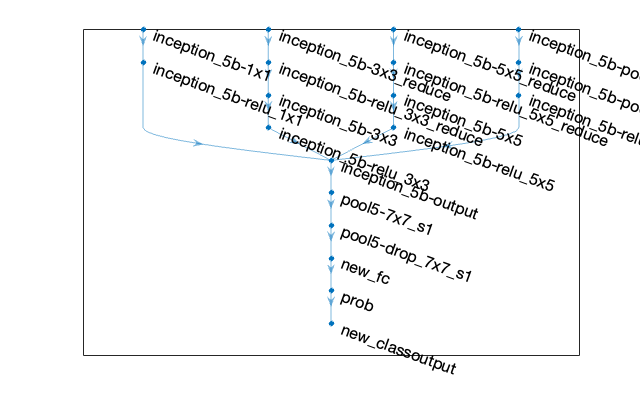


    numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])


%Freeze initial layers
layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);

%Train Network
pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

net = trainNetwork(augimdsTrain,lgraph,options);

%Classify validation images
[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.9000

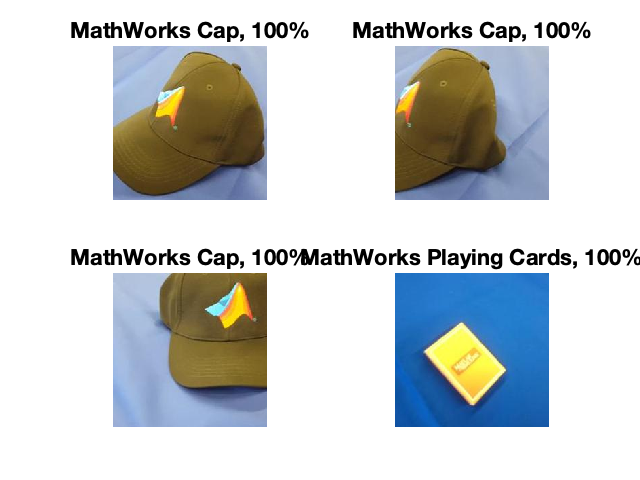



idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end

**ii) AlexNet CNN**

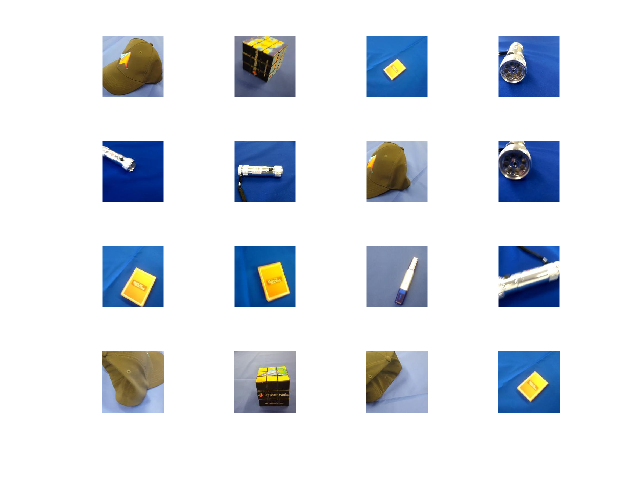

%Alexnet is a convolutional neural network that is 8 layers deep
%Very accurate out the box using "MerchData"

%Create image data store
    imds = imageDatastore('MerchData', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

%Split up the traing and testing data
    [imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

    numTrainImages = numel(imdsTrain.Labels);
    idx = randperm(numTrainImages,16);
    figure
    for i = 1:16
        subplot(4,4,i)
        I = readimage(imdsTrain,idx(i));
        imshow(I)
    end

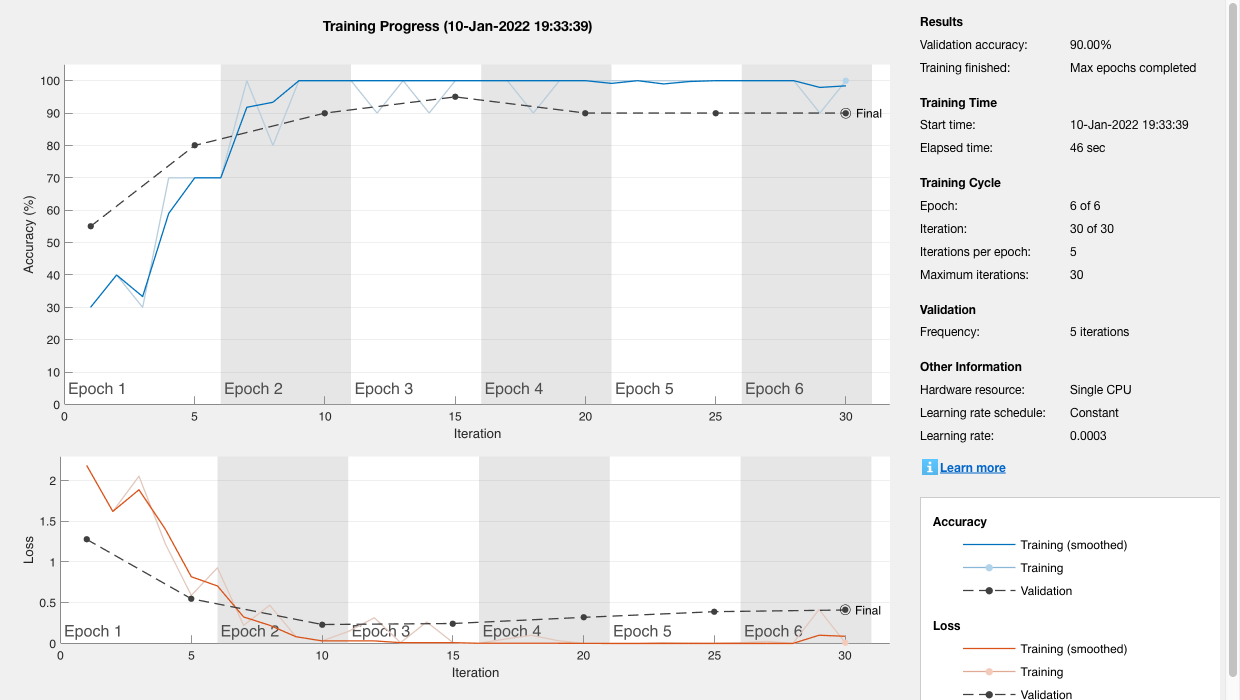

    
%Setup and using alexnet convolutional neural network   
    net = alexnet;
    
    %Use analyzeNetwork to display the network architecture information about the network layers.
    analyzeNetwork(net)


    %image input layer using specific size images.
    inputSize = net.Layers(1).InputSize

inputSize =    227   227     3


    
    %Extracting all of the layers except for the last three
    layersTransfer = net.Layers(1:end-3);
    
    numClasses = numel(categories(imdsTrain.Labels))

numClasses = 5

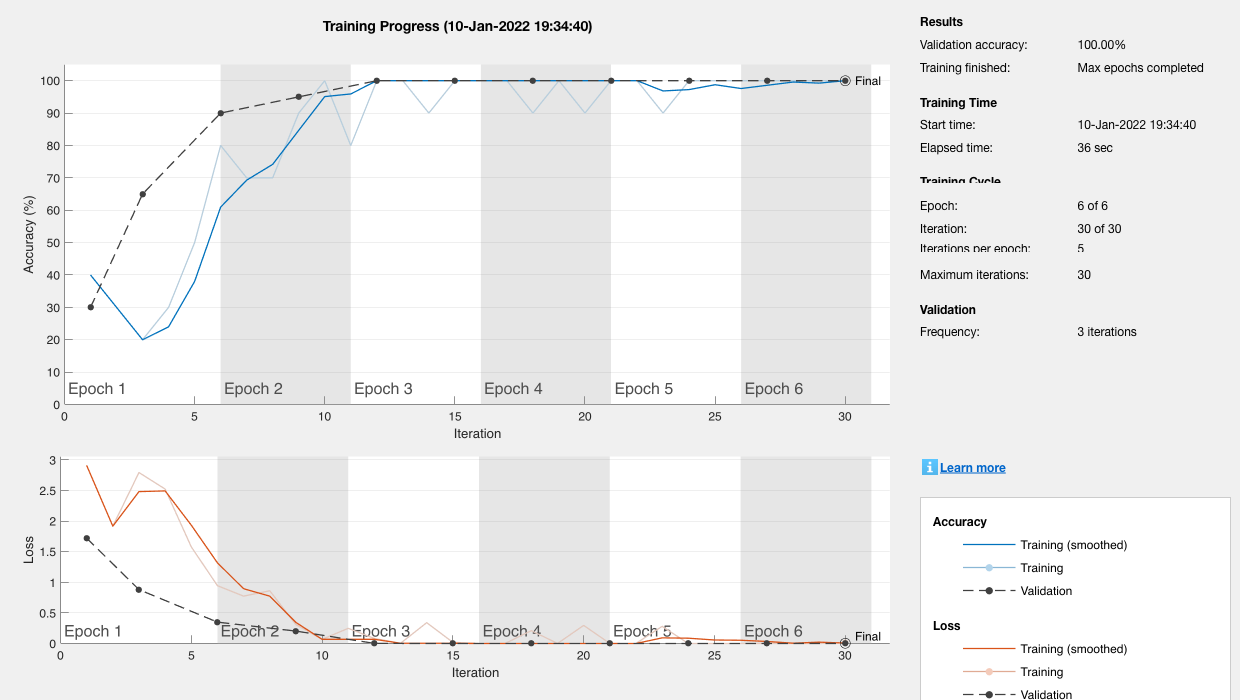

    
    %Replace the last three layers with a fully connected layer, a softmax layer, and a classification output layer.
    layers = [
        layersTransfer
        fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
        softmaxLayer
        classificationLayer];
    
%Requires images of size 227 by 227 by 3

    pixelRange = [-30 30];
    imageAugmenter = imageDataAugmenter( ...
        'RandXReflection',true, ...
        'RandXTranslation',pixelRange, ...
        'RandYTranslation',pixelRange);
    augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
        'DataAugmentation',imageAugmenter);
    
    %Automatically resize the validation images without data augmentation
    augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);
    
%Training using the files from the merchdata set
%Specifying the training options
%Fast learning in new layers and slower learning in the others
%'epoch' = full training cycle using the entire training data set 

    options = trainingOptions('sgdm', ...
        'MiniBatchSize',10, ...
        'MaxEpochs',6, ...
        'InitialLearnRate',1e-4, ...
        'Shuffle','every-epoch', ...
        'ValidationData',augimdsValidation, ...
        'ValidationFrequency',3, ...
        'Verbose',false, ...
        'Plots','training-progress');

    %Training the network consisting of transferred and new layers.
    %Opens in a new window - realtime
    netTransfer = trainNetwork(augimdsTrain,layers,options);

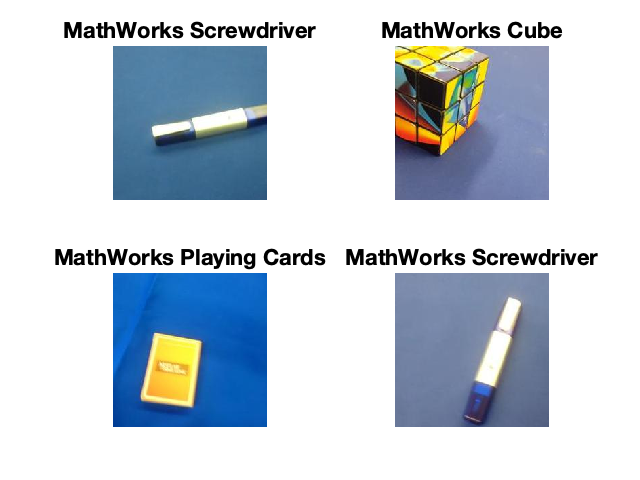


%Classifying the validation images using the network
    [YPred,scores] = classify(netTransfer,augimdsValidation);
    
    idx = randperm(numel(imdsValidation.Files),4);
    figure
    for i = 1:4
        subplot(2,2,i)
        I = readimage(imdsValidation,idx(i));
        imshow(I)
        label = YPred(idx(i));
        title(string(label));
    end


%Checking Accuracy
    %Display four validation images with predicted labels.
    YValidation = imdsValidation.Labels;
    accuracy = mean(YPred == YValidation)

accuracy = 1

**KNN**


%Check and load data
    if ~exist('./MerchData', 'dir')
        error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
    end
    
    
    
% load the dataset
    data = readcell('./Coursework/MerchData.csv');
    
    % <my comment removed>:
    data(1:1:10, 1:1:end)

ans = 10×2 cell array
    {'filesize'}    {'object'}
    {[    6070]}    {'Hat'   }
    {[    4472]}    {'Hat'   }
    {[    3997]}    {'Hat'   }
    {[    5023]}    {'Hat'   }
    {[    5427]}    {'Hat'   }
    {[    5410]}    {'Hat'   }
    {[    5003]}    {'Hat'   }
    {[    4696]}    {'Hat'   }
    {[    4220]}    {'Hat'   }


    data(1, :) = [];
    
    % <my comment removed>:
    data = data(randperm(size(data,1)), :);


%separating training and testing data
    rng(0); % please leave this re-seeding of the random number generator in place so we can compare results   
    %
    nTest = round(0.4 * size(data,1))

nTest = 30

    data_test = data(1:1:nTest, :);
    data_train = data(nTest+1:1:end, :);


%Creating labels
    %Setting the label index to 2
    label_index = 2;
    %Populate 'test_labels' with a categorical containing test data and labels
    test_labels = categorical(data_test(:, label_index));
    test_examples = cell2mat(data_test(:, 1:end~=label_index));
    %Populate 'train_labels' with a categorical containing test data and labels
    train_labels = categorical(data_train(:, label_index));
    train_examples = cell2mat(data_train(:, 1:end~=label_index));


% training the knn classifier
    
    m_knn = fitcknn(train_examples, train_labels)

m_knn =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Cards    Cube    Hat    Screwdriver    Torch]
           ScoreTransform: 'none'
          NumObservations: 45
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


    
    m_nb = fitcnb(train_examples, train_labels)

m_nb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [Cards    Cube    Hat    Screwdriver    Torch]
            ScoreTransform: 'none'
           NumObservations: 45
         DistributionNames: {'normal'}
    DistributionParameters: {5×1 cell}


  Properties, Methods


    
    m_dt = fitctree(train_examples, train_labels)

m_dt =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Cards    Cube    Hat    Screwdriver    Torch]
           ScoreTransform: 'none'
          NumObservations: 45


  Properties, Methods


    
    m_ann = fitcnet(train_examples, train_labels)

m_ann =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Cards    Cube    Hat    Screwdriver    Torch]
           ScoreTransform: 'none'
          NumObservations: 45
               LayerSizes: 10
              Activations: 'relu'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [3×7 table]


  Properties, Methods


    
    m_svm = fitcecoc(train_examples, train_labels)

m_svm =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Cards    Cube    Hat    Screwdriver    Torch]
           ScoreTransform: 'none'
           BinaryLearners: {10×1 cell}
               CodingName: 'onevsone'


  Properties, Methods




%use trained classifier for prediction
    %Using the trained classifier to predict using the 'test_examples'
    predictions = predict(m_knn, test_examples);
    
    %Using the trained classifier to predict using the 'test_examples'
    predictions1 = predict(m_nb, test_examples);
    
    %Using the trained classifier to predict using the 'test_examples'
    predictions2 = predict(m_dt, test_examples);
    
    %Using the trained classifier to predict using the 'test_examples'
    predictions3 = predict(m_ann, test_examples);
    
   %Using the trained classifier to predict using the 'test_examples'
    predictions4 = predict(m_svm, test_examples);


%Evaluate classifiers performance
    [c, order] = confusionmat(test_labels, predictions)

c =      1     0     0     1     0
     1     3     2     0     1
     3     0     1     0     1
     4     0     0     3     1
     4     1     2     0     1


order = 5×1 categorical array
     Cards 
     Cube 
     Hat 
     Screwdriver 
     Torch 


    
    %Create and output a confusion chart using the test_labels and predictions
    confusionchart(test_labels, predictions)
  
    confusionchart(test_labels, predictions1)

    confusionchart(test_labels, predictions2)

    confusionchart(test_labels, predictions3)

    confusionchart(test_labels, predictions4)


    %Output accuracy
    p = sum(diag(c)) / sum(c(1:1:end))

p = 0.3000

**Functions (in order of use):**

knn fit

knn calculate distance

knn predict

get brightness - fin

image to gray - 

get edges 

image gradient xy

get hogs

image gradient

extract hog features

get bag

get words

function b = get_brightness(im)
    size(im)
    x = size(im)
               
    n = x(1,2) * x(1,2)
                
    %Output the image
    imshow(im);
    %calculate average brightness of an image
    brightness = mean2(im)
    imageArray = []
    imageArray = im
    summedImage = sum(imageArray(),"all")
    finbri = summedImage / n
    b = finbri
end


function edges = get_edges(im)
    edges = [0 0];

    surf(im, 'EdgeColor', 'none');

    im = im2gray(im);
    imshow(im);
    [Gx, Gy] = imgradientxy(im, 'Prewitt');

    abs(Gy);
    abs(Gx);

    Gy(Gy>45)
    Gx(Gx<45)

    imshow(Gy)
    imshow(Gx)
    
    Gy1 = sum(Gy);
    Gx1 = sum(Gx);

    edges = [Gy Gx];
end


function h = get_hogs(im)
    h = [];

    [Gx, Gy] = imgradientxy(im, 'Prewitt');
    [Gmag, Gdir] = imgradient(Gx, Gy);
    
    imagesc(Gmag);
    imagesc(Gdir);
    
    CELLSIZE = [16 16];
    [h, v] = extractHOGFeatures(im, 'CellSize', CELLSIZE, ...
    'BlockSize', [floor(size(im,1)/CELLSIZE(1)) floor(size(im,2)/CELLSIZE(2))], ...
    'UseSignedOrientation', true);
    
    imshow(im);
    hold('on')
    v.plot();
    h
    
    hold("off")%bar chart will not show without this
    bar(h)
end


function words = get_words(H)
    rng(0);

    words = [];
    bag= [];

    words = bagOfFeatures(training);
    im = training.readimage(1);
    im = im2gray(im);
    bag = words.encode(im);

    words = sum(bag)
end


%Extension Functions
    function im_g = my_im2gray(im)
    
        im_g = [];
    
        img = im; % RGB image
        %img = ind2rgb(im,map);
        img = im2double(img); % convert image to double datatype
        r = img(:,:,1);
        g = img(:,:,2);
        b = img(:,:,3);
            
        %gray_image; % image you get after adding three channels
        gray_image = im2uint8(gray_image);
    
        im_g = gray_image
    end


    function [Gmag, Gdir] = my_imgradient(Gx, Gy)

    Gmag = [];
    Gdir = []; 
    
    

    end